# Machine Learning: Programming Exercise 7

## *K*-Means Clustering and Principal Component Analysis

In this exercise, you will implement the *K*-means clustering algorithm and apply it to compress an image. In the second part, you will use principal component analysis to find a low-dimensional representation of face images.

### Files needed for this exercise

- `ex7.mlx` - MATLAB Live Script that steps you through the exercise

- `ex7data1.mat` - Example Dataset for PCA

- `ex7data2.mat` - Example Dataset for K-means

- `ex7faces.mat` - Faces Dataset

- bird small.png - Example Image

- `displayData.m` - Displays 2D data stored in a matrix

- `drawLine.m` - Draws a line over an exsiting figure

- `plotDataPoints.m` - Initialization for K-means centroids

- `plotProgresskMeans.m` - Plots each step of K-means as it proceeds

- `runkMeans.m` - Runs the K-means algorithm

- `submit.m` - Submission script that sends your solutions to our servers

- *`pca.m` - Perform principal component analysis

- *`projectData.m` - Projects a data set into a lower dimensional space

- *`recoverData.m` - Recovers the original data from the projection

- *`findClosestCentroids.m` - Find closest centroids (used in K-means)

- *`computeCentroids.m` - Compute centroid means (used in K-means)

- *`kMeansInitCentroids.m` - Initialization for K-means centroids

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex7' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                       computeCentroids.m      ex7_companion.mlx       featureNormalize.m      pca.m                   recoverData.m           
..                      displayData.m           ex7data1.mat            findClosestCentroids.m  plotDataPoints.m        runkMeans.m             
bird_small.mat          drawLine.m              ex7data2.mat            kMeansInitCentroids.m   plotProgresskMeans.m    submit.m                
bird_small.png          ex7.mlx                 ex7faces.mat            lib                     projectData.m           token.mat               



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. *K*-Means Clustering

In this this exercise, you will implement the *K*-means algorithm and use it for image compression. You will first start on an example 2D dataset that will help you gain an intuition of how the *K*-means algorithm works. After that, you wil use the *K*-means algorithm for image compression by reducing the number of colors that occur in an image to only those that are most common in that image.

### 1.1 Implementing *K*-means

The K-means algorithm is a method to automatically cluster similar data examples together. Concretely, you are given a training set $\{x^{(1)},\ldots x^{(m)}\}$ (where $x^{(i)}\in \mathbb{R}^n$), and want to group the data into a few cohesive 'clusters'. The intuition behind *K*-means is an iterative procedure that starts by guessing the initial centroids, and then refines this guess by repeatedly assigning examples to their closest centroids and then recomputing the centroids based on the assignments.

    The *K*-means algorithm is as follows:

The inner-loop of the algorithm repeatedly carries out two steps: 

- Assigning each training example $x^{(i)}$ to its closest centroid

- Recomputing the mean of each centroid using the points assigned to it. 

The *K*-means algorithm will always converge to some final set of means for the centroids. Note that the converged solution may not always be ideal and depends on the initial setting of the centroids. Therefore, in practice the K-means algorithm is usually run a few times with dierent random initializations. One way to choose between these different solutions from different random initializations is to choose the one with the lowest cost function value (distortion). You will implement the two phases of the K-means algorithm separately in the next sections.

#### 1.1.1 Finding closest centroids

In the 'cluster assignment' phase of the *K*-means algorithm, the algorithm assigns every training example $x^{(i)}$ to its closest centroid, given the current positions of centroids. Specically, for every example $i$ we set 


$$c^{(i)} :=j \quad\text{that minimizes}\quad\left||x^{(i)}-\mu_j\right||^2,$$


where $c^{(i)}$ is the index of the centroid that is closest to $x^{(i)}$, and $\mu_j$ is the position (value) of the $j$-th centroid. Note that $c^{(i)}$ corresponds to `idx(i)` in the starter code.

    Your task is to complete the code in `findClosestCentroids.m`. This function takes the data matrix `X` and the locations of all centroids inside centroids and should output a one-dimensional array `idx` that holds the index (a value in $\{1,\ldots,K\}$, where $K$ is total number of centroids) of the closest centroid to every training example. You can implement this using a loop over every training example and every centroid. 

    Once you have completed the code in `findClosestCentroids.m`, the code below will run your code and you should see the output `[1 3 2]` corresponding to the centroid assignments for the first 3 examples.

% Load an example dataset that we will be using
load('ex7data2.mat');

% Select an initial set of centroids
K = 3; % 3 Centroids
initial_centroids = [3 3; 6 2; 8 5];

% Find the closest centroids for the examples using the initial_centroids
idx = findClosestCentroids(X, initial_centroids);

min_cent =      0     0
     0     0
     0     0


point =     1.8421    4.6076


min_cent =     3.9251         0
         0         0
         0         0


min_cent =     3.9251    1.0000
         0         0
         0         0


min_cent =     3.9251    1.0000
   24.0877         0
         0         0


min_cent =     3.9251    1.0000
   24.0877    2.0000
         0         0


min_cent =     3.9251    1.0000
   24.0877    2.0000
   38.0740         0


min_cent =     3.9251    1.0000
   24.0877    2.0000
   38.0740    3.0000


idx_1 =     3.9251    1.0000


i =      1     1


idx =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


point =     5.6586    4.8000


min_cent =    10.3079    1.0000
   24.0877    2.0000
   38.0740    3.0000


min_cent =    10.3079    1.0000
   24.0877    2.0000
   38.0740    3.0000


min_cent =    10.3079    1.0000
    7.9564    2.0000
   38.0740    3.0000


min_cent =    10.3079    1.0000
    7.9564    2.0000
   38.0740    3.0000


min_cent =    10.3079    1.0000
    7.9564    2.0000
    5.5222    3.0000


min_cent =    10.3079    1.0000
    7.9564    2.0000
    5.5222    3.0000


idx_1 =     5.5222    1.0000


i =      3     1


idx =      1
     3
     0
     0
     0
     0
     0
     0
     0
     0


point =     6.3526    3.2909


min_cent =    11.3244    1.0000
    7.9564    2.0000
    5.5222    3.0000


min_cent =    11.3244    1.0000
    7.9564    2.0000
    5.5222    3.0000


min_cent =    11.3244    1.0000
    1.7906    2.0000
    5.5222    3.0000


min_cent =    11.3244    1.0000
    1.7906    2.0000
    5.5222    3.0000


min_cent =    11.3244    1.0000
    1.7906    2.0000
    5.6352    3.0000


min_cent =    11.3244    1.0000
    1.7906    2.0000
    5.6352    3.0000


idx_1 =     1.7906    1.0000


i =      2     1


idx =      1
     3
     2
     0
     0
     0
     0
     0
     0
     0


point =     2.9040    4.6122


min_cent =     2.6084    1.0000
    1.7906    2.0000
    5.6352    3.0000


min_cent =     2.6084    1.0000
    1.7906    2.0000
    5.6352    3.0000


min_cent =     2.6084    1.0000
   16.4087    2.0000
    5.6352    3.0000


min_cent =     2.6084    1.0000
   16.4087    2.0000
    5.6352    3.0000


min_cent =     2.6084    1.0000
   16.4087    2.0000
   26.1194    3.0000


min_cent =     2.6084    1.0000
   16.4087    2.0000
   26.1194    3.0000


idx_1 =     2.6084    1.0000


i =      1     1


idx =      1
     3
     2
     1
     0
     0
     0
     0
     0
     0


point =     3.2320    4.9399


min_cent =     3.8170    1.0000
   16.4087    2.0000
   26.1194    3.0000


min_cent =     3.8170    1.0000
   16.4087    2.0000
   26.1194    3.0000


min_cent =     3.8170    1.0000
   16.3049    2.0000
   26.1194    3.0000


min_cent =     3.8170    1.0000
   16.3049    2.0000
   26.1194    3.0000


min_cent =     3.8170    1.0000
   16.3049    2.0000
   22.7376    3.0000


min_cent =     3.8170    1.0000
   16.3049    2.0000
   22.7376    3.0000


idx_1 =     3.8170    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     0
     0
     0
     0
     0


point =     1.2479    4.9327


min_cent =     6.8050    1.0000
   16.3049    2.0000
   22.7376    3.0000


min_cent =     6.8050    1.0000
   16.3049    2.0000
   22.7376    3.0000


min_cent =     6.8050    1.0000
   31.1828    2.0000
   22.7376    3.0000


min_cent =     6.8050    1.0000
   31.1828    2.0000
   22.7376    3.0000


min_cent =     6.8050    1.0000
   31.1828    2.0000
   45.5951    3.0000


min_cent =     6.8050    1.0000
   31.1828    2.0000
   45.5951    3.0000


idx_1 =     6.8050    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     0
     0
     0
     0


point =     1.9762    4.4349


min_cent =     3.1071    1.0000
   31.1828    2.0000
   45.5951    3.0000


min_cent =     3.1071    1.0000
   31.1828    2.0000
   45.5951    3.0000


min_cent =     3.1071    1.0000
   22.1197    2.0000
   45.5951    3.0000


min_cent =     3.1071    1.0000
   22.1197    2.0000
   45.5951    3.0000


min_cent =     3.1071    1.0000
   22.1197    2.0000
   36.6055    3.0000


min_cent =     3.1071    1.0000
   22.1197    2.0000
   36.6055    3.0000


idx_1 =     3.1071    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     0
     0
     0


point =     2.2345    5.0555


min_cent =     4.8109    1.0000
   22.1197    2.0000
   36.6055    3.0000


min_cent =     4.8109    1.0000
   22.1197    2.0000
   36.6055    3.0000


min_cent =     4.8109    1.0000
   23.5146    2.0000
   36.6055    3.0000


min_cent =     4.8109    1.0000
   23.5146    2.0000
   36.6055    3.0000


min_cent =     4.8109    1.0000
   23.5146    2.0000
   33.2436    3.0000


min_cent =     4.8109    1.0000
   23.5146    2.0000
   33.2436    3.0000


idx_1 =     4.8109    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     0
     0


point =     2.9834    4.8405


min_cent =     3.3876    1.0000
   23.5146    2.0000
   33.2436    3.0000


min_cent =     3.3876    1.0000
   23.5146    2.0000
   33.2436    3.0000


min_cent =     3.3876    1.0000
   17.1681    2.0000
   33.2436    3.0000


min_cent =     3.3876    1.0000
   17.1681    2.0000
   33.2436    3.0000


min_cent =     3.3876    1.0000
   17.1681    2.0000
   25.1917    3.0000


min_cent =     3.3876    1.0000
   17.1681    2.0000
   25.1917    3.0000


idx_1 =     3.3876    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     0


point =     2.9797    4.8067


min_cent =     3.2646    1.0000
   17.1681    2.0000
   25.1917    3.0000


min_cent =     3.2646    1.0000
   17.1681    2.0000
   25.1917    3.0000


min_cent =     3.2646    1.0000
   16.9998    2.0000
   25.1917    3.0000


min_cent =     3.2646    1.0000
   16.9998    2.0000
   25.1917    3.0000


min_cent =     3.2646    1.0000
   16.9998    2.0000
   25.2407    3.0000


min_cent =     3.2646    1.0000
   16.9998    2.0000
   25.2407    3.0000


idx_1 =     3.2646    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1150    5.3737


min_cent =     6.4179    1.0000
   16.9998    2.0000
   25.2407    3.0000


min_cent =     6.4179    1.0000
   16.9998    2.0000
   25.2407    3.0000


min_cent =     6.4179    1.0000
   26.4756    2.0000
   25.2407    3.0000


min_cent =     6.4179    1.0000
   26.4756    2.0000
   25.2407    3.0000


min_cent =     6.4179    1.0000
   26.4756    2.0000
   34.7733    3.0000


min_cent =     6.4179    1.0000
   26.4756    2.0000
   34.7733    3.0000


idx_1 =     6.4179    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1217    5.2085


min_cent =     5.6491    1.0000
   26.4756    2.0000
   34.7733    3.0000


min_cent =     5.6491    1.0000
   26.4756    2.0000
   34.7733    3.0000


min_cent =     5.6491    1.0000
   25.3360    2.0000
   34.7733    3.0000


min_cent =     5.6491    1.0000
   25.3360    2.0000
   34.7733    3.0000


min_cent =     5.6491    1.0000
   25.3360    2.0000
   34.5980    3.0000


min_cent =     5.6491    1.0000
   25.3360    2.0000
   34.5980    3.0000


idx_1 =     5.6491    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.5144    4.7700


min_cent =     5.3402    1.0000
   25.3360    2.0000
   34.5980    3.0000


min_cent =     5.3402    1.0000
   25.3360    2.0000
   34.5980    3.0000


min_cent =     5.3402    1.0000
   27.7941    2.0000
   34.5980    3.0000


min_cent =     5.3402    1.0000
   27.7941    2.0000
   34.5980    3.0000


min_cent =     5.3402    1.0000
   27.7941    2.0000
   42.1165    3.0000


min_cent =     5.3402    1.0000
   27.7941    2.0000
   42.1165    3.0000


idx_1 =     5.3402    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1698    5.2744


min_cent =     5.8619    1.0000
   27.7941    2.0000
   42.1165    3.0000


min_cent =     5.8619    1.0000
   27.7941    2.0000
   42.1165    3.0000


min_cent =     5.8619    1.0000
   25.3919    2.0000
   42.1165    3.0000


min_cent =     5.8619    1.0000
   25.3919    2.0000
   42.1165    3.0000


min_cent =     5.8619    1.0000
   25.3919    2.0000
   34.0666    3.0000


min_cent =     5.8619    1.0000
   25.3919    2.0000
   34.0666    3.0000


idx_1 =     5.8619    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.4185    4.8831


min_cent =    10.2102    1.0000
   25.3919    2.0000
   34.0666    3.0000


min_cent =    10.2102    1.0000
   25.3919    2.0000
   34.0666    3.0000


min_cent =    10.2102    1.0000
   39.4653    2.0000
   34.0666    3.0000


min_cent =    10.2102    1.0000
   39.4653    2.0000
   34.0666    3.0000


min_cent =    10.2102    1.0000
   39.4653    2.0000
   57.4924    3.0000


min_cent =    10.2102    1.0000
   39.4653    2.0000
   57.4924    3.0000


idx_1 =    10.2102    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.4705    4.8042


min_cent =     3.5354    1.0000
   39.4653    2.0000
   57.4924    3.0000


min_cent =     3.5354    1.0000
   39.4653    2.0000
   57.4924    3.0000


min_cent =     3.5354    1.0000
   20.3206    2.0000
   57.4924    3.0000


min_cent =     3.5354    1.0000
   20.3206    2.0000
   57.4924    3.0000


min_cent =     3.5354    1.0000
   20.3206    2.0000
   30.6133    3.0000


min_cent =     3.5354    1.0000
   20.3206    2.0000
   30.6133    3.0000


idx_1 =     3.5354    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.0607    4.9950


min_cent =     5.1052    1.0000
   20.3206    2.0000
   30.6133    3.0000


min_cent =     5.1052    1.0000
   20.3206    2.0000
   30.6133    3.0000


min_cent =     5.1052    1.0000
   12.7312    2.0000
   30.6133    3.0000


min_cent =     5.1052    1.0000
   12.7312    2.0000
   30.6133    3.0000


min_cent =     5.1052    1.0000
   12.7312    2.0000
   15.5182    3.0000


min_cent =     5.1052    1.0000
   12.7312    2.0000
   15.5182    3.0000


idx_1 =     5.1052    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0071    4.6790


min_cent =     2.8190    1.0000
   12.7312    2.0000
   15.5182    3.0000


min_cent =     2.8190    1.0000
   12.7312    2.0000
   15.5182    3.0000


min_cent =     2.8190    1.0000
   16.1344    2.0000
   15.5182    3.0000


min_cent =     2.8190    1.0000
   16.1344    2.0000
   15.5182    3.0000


min_cent =     2.8190    1.0000
   16.1344    2.0000
   25.0322    3.0000


min_cent =     2.8190    1.0000
   16.1344    2.0000
   25.0322    3.0000


idx_1 =     2.8190    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.6663    4.8719


min_cent =     8.9500    1.0000
   16.1344    2.0000
   25.0322    3.0000


min_cent =     8.9500    1.0000
   16.1344    2.0000
   25.0322    3.0000


min_cent =     8.9500    1.0000
   36.6958    2.0000
   25.0322    3.0000


min_cent =     8.9500    1.0000
   36.6958    2.0000
   25.0322    3.0000


min_cent =     8.9500    1.0000
   36.6958    2.0000
   53.7992    3.0000


min_cent =     8.9500    1.0000
   36.6958    2.0000
   53.7992    3.0000


idx_1 =     8.9500    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1622    4.8366


min_cent =     3.3993    1.0000
   36.6958    2.0000
   53.7992    3.0000


min_cent =     3.3993    1.0000
   36.6958    2.0000
   53.7992    3.0000


min_cent =     3.3993    1.0000
   16.0994    2.0000
   53.7992    3.0000


min_cent =     3.3993    1.0000
   16.0994    2.0000
   53.7992    3.0000


min_cent =     3.3993    1.0000
   16.0994    2.0000
   23.4311    3.0000


min_cent =     3.3993    1.0000
   16.0994    2.0000
   23.4311    3.0000


idx_1 =     3.3993    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.5116    4.9105


min_cent =     9.8425    1.0000
   16.0994    2.0000
   23.4311    3.0000


min_cent =     9.8425    1.0000
   16.0994    2.0000
   23.4311    3.0000


min_cent =     9.8425    1.0000
   38.5942    2.0000
   23.4311    3.0000


min_cent =     9.8425    1.0000
   38.5942    2.0000
   23.4311    3.0000


min_cent =     9.8425    1.0000
   38.5942    2.0000
   56.0848    3.0000


min_cent =     9.8425    1.0000
   38.5942    2.0000
   56.0848    3.0000


idx_1 =     9.8425    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1343    4.9618


min_cent =     3.8666    1.0000
   38.5942    2.0000
   56.0848    3.0000


min_cent =     3.8666    1.0000
   38.5942    2.0000
   56.0848    3.0000


min_cent =     3.8666    1.0000
   16.9845    2.0000
   56.0848    3.0000


min_cent =     3.8666    1.0000
   16.9845    2.0000
   56.0848    3.0000


min_cent =     3.8666    1.0000
   16.9845    2.0000
   23.6767    3.0000


min_cent =     3.8666    1.0000
   16.9845    2.0000
   23.6767    3.0000


idx_1 =     3.8666    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0497    5.6241


min_cent =     7.7891    1.0000
   16.9845    2.0000
   23.6767    3.0000


min_cent =     7.7891    1.0000
   16.9845    2.0000
   23.6767    3.0000


min_cent =     7.7891    1.0000
   28.7389    2.0000
   23.6767    3.0000


min_cent =     7.7891    1.0000
   28.7389    2.0000
   23.6767    3.0000


min_cent =     7.7891    1.0000
   28.7389    2.0000
   35.7951    3.0000


min_cent =     7.7891    1.0000
   28.7389    2.0000
   35.7951    3.0000


idx_1 =     7.7891    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.6658    5.2440


min_cent =    10.4839    1.0000
   28.7389    2.0000
   35.7951    3.0000


min_cent =    10.4839    1.0000
   28.7389    2.0000
   35.7951    3.0000


min_cent =    10.4839    1.0000
   38.9769    2.0000
   35.7951    3.0000


min_cent =    10.4839    1.0000
   38.9769    2.0000
   35.7951    3.0000


min_cent =    10.4839    1.0000
   38.9769    2.0000
   53.8496    3.0000


min_cent =    10.4839    1.0000
   38.9769    2.0000
   53.8496    3.0000


idx_1 =    10.4839    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.0173    4.8447


min_cent =     7.3341    1.0000
   38.9769    2.0000
   53.8496    3.0000


min_cent =     7.3341    1.0000
   38.9769    2.0000
   53.8496    3.0000


min_cent =     7.3341    1.0000
   32.9196    2.0000
   53.8496    3.0000


min_cent =     7.3341    1.0000
   32.9196    2.0000
   53.8496    3.0000


min_cent =     7.3341    1.0000
   32.9196    2.0000
   48.7819    3.0000


min_cent =     7.3341    1.0000
   32.9196    2.0000
   48.7819    3.0000


idx_1 =     7.3341    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1789    5.2976


min_cent =     5.9531    1.0000
   32.9196    2.0000
   48.7819    3.0000


min_cent =     5.9531    1.0000
   32.9196    2.0000
   48.7819    3.0000


min_cent =     5.9531    1.0000
   25.4746    2.0000
   48.7819    3.0000


min_cent =     5.9531    1.0000
   25.4746    2.0000
   48.7819    3.0000


min_cent =     5.9531    1.0000
   25.4746    2.0000
   33.9733    3.0000


min_cent =     5.9531    1.0000
   25.4746    2.0000
   33.9733    3.0000


idx_1 =     5.9531    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.8596    5.2604


min_cent =     5.1292    1.0000
   25.4746    2.0000
   33.9733    3.0000


min_cent =     5.1292    1.0000
   25.4746    2.0000
   33.9733    3.0000


min_cent =     5.1292    1.0000
   20.4923    2.0000
   33.9733    3.0000


min_cent =     5.1292    1.0000
   20.4923    2.0000
   33.9733    3.0000


min_cent =     5.1292    1.0000
   20.4923    2.0000
   26.4913    3.0000


min_cent =     5.1292    1.0000
   20.4923    2.0000
   26.4913    3.0000


idx_1 =     5.1292    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.3088    5.3016


min_cent =     8.1574    1.0000
   20.4923    2.0000
   26.4913    3.0000


min_cent =     8.1574    1.0000
   20.4923    2.0000
   26.4913    3.0000


min_cent =     8.1574    1.0000
   32.9076    2.0000
   26.4913    3.0000


min_cent =     8.1574    1.0000
   32.9076    2.0000
   26.4913    3.0000


min_cent =     8.1574    1.0000
   32.9076    2.0000
   44.8628    3.0000


min_cent =     8.1574    1.0000
   32.9076    2.0000
   44.8628    3.0000


idx_1 =     8.1574    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.9925    5.0157


min_cent =     8.0929    1.0000
   32.9076    2.0000
   44.8628    3.0000


min_cent =     8.0929    1.0000
   32.9076    2.0000
   44.8628    3.0000


min_cent =     8.0929    1.0000
   34.1690    2.0000
   44.8628    3.0000


min_cent =     8.0929    1.0000
   34.1690    2.0000
   44.8628    3.0000


min_cent =     8.0929    1.0000
   34.1690    2.0000
   49.1048    3.0000


min_cent =     8.0929    1.0000
   34.1690    2.0000
   49.1048    3.0000


idx_1 =     8.0929    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.4037    4.5753


min_cent =     5.0296    1.0000
   34.1690    2.0000
   49.1048    3.0000


min_cent =     5.0296    1.0000
   34.1690    2.0000
   49.1048    3.0000


min_cent =     5.0296    1.0000
   27.7578    2.0000
   49.1048    3.0000


min_cent =     5.0296    1.0000
   27.7578    2.0000
   49.1048    3.0000


min_cent =     5.0296    1.0000
   27.7578    2.0000
   43.6912    3.0000


min_cent =     5.0296    1.0000
   27.7578    2.0000
   43.6912    3.0000


idx_1 =     5.0296    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.6605    5.1962


min_cent =     4.9387    1.0000
   27.7578    2.0000
   43.6912    3.0000


min_cent =     4.9387    1.0000
   27.7578    2.0000
   43.6912    3.0000


min_cent =     4.9387    1.0000
   21.3684    2.0000
   43.6912    3.0000


min_cent =     4.9387    1.0000
   21.3684    2.0000
   43.6912    3.0000


min_cent =     4.9387    1.0000
   21.3684    2.0000
   28.5491    3.0000


min_cent =     4.9387    1.0000
   21.3684    2.0000
   28.5491    3.0000


idx_1 =     4.9387    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.8000    5.1153


min_cent =     4.5144    1.0000
   21.3684    2.0000
   28.5491    3.0000


min_cent =     4.5144    1.0000
   21.3684    2.0000
   28.5491    3.0000


min_cent =     4.5144    1.0000
   19.9451    2.0000
   28.5491    3.0000


min_cent =     4.5144    1.0000
   19.9451    2.0000
   28.5491    3.0000


min_cent =     4.5144    1.0000
   19.9451    2.0000
   27.0537    3.0000


min_cent =     4.5144    1.0000
   19.9451    2.0000
   27.0537    3.0000


idx_1 =     4.5144    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0700    4.6847


min_cent =     3.7031    1.0000
   19.9451    2.0000
   27.0537    3.0000


min_cent =     3.7031    1.0000
   19.9451    2.0000
   27.0537    3.0000


min_cent =     3.7031    1.0000
   22.6527    2.0000
   27.0537    3.0000


min_cent =     3.7031    1.0000
   22.6527    2.0000
   27.0537    3.0000


min_cent =     3.7031    1.0000
   22.6527    2.0000
   35.2649    3.0000


min_cent =     3.7031    1.0000
   22.6527    2.0000
   35.2649    3.0000


idx_1 =     3.7031    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2977    5.5921


min_cent =     6.8073    1.0000
   22.6527    2.0000
   35.2649    3.0000


min_cent =     6.8073    1.0000
   22.6527    2.0000
   35.2649    3.0000


min_cent =     6.8073    1.0000
   20.2055    2.0000
   35.2649    3.0000


min_cent =     6.8073    1.0000
   20.2055    2.0000
   35.2649    3.0000


min_cent =     6.8073    1.0000
   20.2055    2.0000
   22.4626    3.0000


min_cent =     6.8073    1.0000
   20.2055    2.0000
   22.4626    3.0000


idx_1 =     6.8073    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8930    4.8904


min_cent =     4.7992    1.0000
   20.2055    2.0000
   22.4626    3.0000


min_cent =     4.7992    1.0000
   20.2055    2.0000
   22.4626    3.0000


min_cent =     4.7992    1.0000
   25.2222    2.0000
   22.4626    3.0000


min_cent =     4.7992    1.0000
   25.2222    2.0000
   22.4626    3.0000


min_cent =     4.7992    1.0000
   25.2222    2.0000
   37.3077    3.0000


min_cent =     4.7992    1.0000
   25.2222    2.0000
   37.3077    3.0000


idx_1 =     4.7992    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5598    5.2640


min_cent =     5.3193    1.0000
   25.2222    2.0000
   37.3077    3.0000


min_cent =     5.3193    1.0000
   25.2222    2.0000
   37.3077    3.0000


min_cent =     5.3193    1.0000
   22.4883    2.0000
   37.3077    3.0000


min_cent =     5.3193    1.0000
   22.4883    2.0000
   37.3077    3.0000


min_cent =     5.3193    1.0000
   22.4883    2.0000
   29.6651    3.0000


min_cent =     5.3193    1.0000
   22.4883    2.0000
   29.6651    3.0000


idx_1 =     5.3193    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.1535    4.6787


min_cent =     6.2273    1.0000
   22.4883    2.0000
   29.6651    3.0000


min_cent =     6.2273    1.0000
   22.4883    2.0000
   29.6651    3.0000


min_cent =     6.2273    1.0000
   30.6634    2.0000
   29.6651    3.0000


min_cent =     6.2273    1.0000
   30.6634    2.0000
   29.6651    3.0000


min_cent =     6.2273    1.0000
   30.6634    2.0000
   46.9773    3.0000


min_cent =     6.2273    1.0000
   30.6634    2.0000
   46.9773    3.0000


idx_1 =     6.2273    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2515    5.4450


min_cent =     6.5383    1.0000
   30.6634    2.0000
   46.9773    3.0000


min_cent =     6.5383    1.0000
   30.6634    2.0000
   46.9773    3.0000


min_cent =     6.5383    1.0000
   25.9192    2.0000
   46.9773    3.0000


min_cent =     6.5383    1.0000
   25.9192    2.0000
   46.9773    3.0000


min_cent =     6.5383    1.0000
   25.9192    2.0000
   33.2432    3.0000


min_cent =     6.5383    1.0000
   25.9192    2.0000
   33.2432    3.0000


idx_1 =     6.5383    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2096    4.9147


min_cent =     4.2908    1.0000
   25.9192    2.0000
   33.2432    3.0000


min_cent =     4.2908    1.0000
   25.9192    2.0000
   33.2432    3.0000


min_cent =     4.2908    1.0000
   22.8625    2.0000
   33.2432    3.0000


min_cent =     4.2908    1.0000
   22.8625    2.0000
   33.2432    3.0000


min_cent =     4.2908    1.0000
   22.8625    2.0000
   33.5360    3.0000


min_cent =     4.2908    1.0000
   22.8625    2.0000
   33.5360    3.0000


idx_1 =     4.2908    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.5914    4.8321


min_cent =     5.3408    1.0000
   22.8625    2.0000
   33.5360    3.0000


min_cent =     5.3408    1.0000
   22.8625    2.0000
   33.5360    3.0000


min_cent =     5.3408    1.0000
   27.4565    2.0000
   33.5360    3.0000


min_cent =     5.3408    1.0000
   27.4565    2.0000
   33.5360    3.0000


min_cent =     5.3408    1.0000
   27.4565    2.0000
   41.0981    3.0000


min_cent =     5.3408    1.0000
   27.4565    2.0000
   41.0981    3.0000


idx_1 =     5.3408    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.6784    5.2690


min_cent =     6.8952    1.0000
   27.4565    2.0000
   41.0981    3.0000


min_cent =     6.8952    1.0000
   27.4565    2.0000
   41.0981    3.0000


min_cent =     6.8952    1.0000
   29.3630    2.0000
   41.0981    3.0000


min_cent =     6.8952    1.0000
   29.3630    2.0000
   41.0981    3.0000


min_cent =     6.8952    1.0000
   29.3630    2.0000
   40.0353    3.0000


min_cent =     6.8952    1.0000
   29.3630    2.0000
   40.0353    3.0000


idx_1 =     6.8952    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5915    4.9259


min_cent =     3.8761    1.0000
   29.3630    2.0000
   40.0353    3.0000


min_cent =     3.8761    1.0000
   29.3630    2.0000
   40.0353    3.0000


min_cent =     3.8761    1.0000
   20.1791    2.0000
   40.0353    3.0000


min_cent =     3.8761    1.0000
   20.1791    2.0000
   40.0353    3.0000


min_cent =     3.8761    1.0000
   20.1791    2.0000
   29.2575    3.0000


min_cent =     3.8761    1.0000
   20.1791    2.0000
   29.2575    3.0000


idx_1 =     3.8761    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.8100    5.5385


min_cent =     6.4801    1.0000
   20.1791    2.0000
   29.2575    3.0000


min_cent =     6.4801    1.0000
   20.1791    2.0000
   29.2575    3.0000


min_cent =     6.4801    1.0000
   22.6973    2.0000
   29.2575    3.0000


min_cent =     6.4801    1.0000
   22.6973    2.0000
   29.2575    3.0000


min_cent =     6.4801    1.0000
   22.6973    2.0000
   27.2265    3.0000


min_cent =     6.4801    1.0000
   22.6973    2.0000
   27.2265    3.0000


idx_1 =     6.4801    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.9531    5.5804


min_cent =    10.8480    1.0000
   22.6973    2.0000
   27.2265    3.0000


min_cent =    10.8480    1.0000
   22.6973    2.0000
   27.2265    3.0000


min_cent =    10.8480    1.0000
   38.2901    2.0000
   27.2265    3.0000


min_cent =    10.8480    1.0000
   38.2901    2.0000
   27.2265    3.0000


min_cent =    10.8480    1.0000
   38.2901    2.0000
   49.9954    3.0000


min_cent =    10.8480    1.0000
   38.2901    2.0000
   49.9954    3.0000


idx_1 =    10.8480    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.5178    5.0384


min_cent =     6.3520    1.0000
   38.2901    2.0000
   49.9954    3.0000


min_cent =     6.3520    1.0000
   38.2901    2.0000
   49.9954    3.0000


min_cent =     6.3520    1.0000
   29.3222    2.0000
   49.9954    3.0000


min_cent =     6.3520    1.0000
   29.3222    2.0000
   49.9954    3.0000


min_cent =     6.3520    1.0000
   29.3222    2.0000
   42.0210    3.0000


min_cent =     6.3520    1.0000
   29.3222    2.0000
   42.0210    3.0000


idx_1 =     6.3520    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2311    5.7843


min_cent =     7.8057    1.0000
   29.3222    2.0000
   42.0210    3.0000


min_cent =     7.8057    1.0000
   29.3222    2.0000
   42.0210    3.0000


min_cent =     7.8057    1.0000
   21.9875    2.0000
   42.0210    3.0000


min_cent =     7.8057    1.0000
   21.9875    2.0000
   42.0210    3.0000


min_cent =     7.8057    1.0000
   21.9875    2.0000
   23.3571    3.0000


min_cent =     7.8057    1.0000
   21.9875    2.0000
   23.3571    3.0000


idx_1 =     7.8057    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5418    4.8110


min_cent =     3.4896    1.0000
   21.9875    2.0000
   23.3571    3.0000


min_cent =     3.4896    1.0000
   21.9875    2.0000
   23.3571    3.0000


min_cent =     3.4896    1.0000
   19.8608    2.0000
   23.3571    3.0000


min_cent =     3.4896    1.0000
   19.8608    2.0000
   23.3571    3.0000


min_cent =     3.4896    1.0000
   19.8608    2.0000
   29.8277    3.0000


min_cent =     3.4896    1.0000
   19.8608    2.0000
   29.8277    3.0000


idx_1 =     3.4896    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.8142    4.7353


min_cent =     3.6741    1.0000
   19.8608    2.0000
   29.8277    3.0000


min_cent =     3.6741    1.0000
   19.8608    2.0000
   29.8277    3.0000


min_cent =     3.6741    1.0000
   12.2593    2.0000
   29.8277    3.0000


min_cent =     3.6741    1.0000
   12.2593    2.0000
   29.8277    3.0000


min_cent =     3.6741    1.0000
   12.2593    2.0000
   17.5908    3.0000


min_cent =     3.6741    1.0000
   12.2593    2.0000
   17.5908    3.0000


idx_1 =     3.6741    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.6850    4.5964


min_cent =     4.2779    1.0000
   12.2593    2.0000
   17.5908    3.0000


min_cent =     4.2779    1.0000
   12.2593    2.0000
   17.5908    3.0000


min_cent =     4.2779    1.0000
   25.3611    2.0000
   17.5908    3.0000


min_cent =     4.2779    1.0000
   25.3611    2.0000
   17.5908    3.0000


min_cent =     4.2779    1.0000
   25.3611    2.0000
   40.0426    3.0000


min_cent =     4.2779    1.0000
   25.3611    2.0000
   40.0426    3.0000


idx_1 =     4.2779    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1778    4.8615


min_cent =     4.1414    1.0000
   25.3611    2.0000
   40.0426    3.0000


min_cent =     4.1414    1.0000
   25.3611    2.0000
   40.0426    3.0000


min_cent =     4.1414    1.0000
   22.7978    2.0000
   40.0426    3.0000


min_cent =     4.1414    1.0000
   22.7978    2.0000
   40.0426    3.0000


min_cent =     4.1414    1.0000
   22.7978    2.0000
   33.9175    3.0000


min_cent =     4.1414    1.0000
   22.7978    2.0000
   33.9175    3.0000


idx_1 =     4.1414    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8173    5.1333


min_cent =     5.9498    1.0000
   22.7978    2.0000
   33.9175    3.0000


min_cent =     5.9498    1.0000
   22.7978    2.0000
   33.9175    3.0000


min_cent =     5.9498    1.0000
   27.3125    2.0000
   33.9175    3.0000


min_cent =     5.9498    1.0000
   27.3125    2.0000
   33.9175    3.0000


min_cent =     5.9498    1.0000
   27.3125    2.0000
   38.2432    3.0000


min_cent =     5.9498    1.0000
   27.3125    2.0000
   38.2432    3.0000


idx_1 =     5.9498    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8578    4.8696


min_cent =     4.8002    1.0000
   27.3125    2.0000
   38.2432    3.0000


min_cent =     4.8002    1.0000
   27.3125    2.0000
   38.2432    3.0000


min_cent =     4.8002    1.0000
   25.3928    2.0000
   38.2432    3.0000


min_cent =     4.8002    1.0000
   25.3928    2.0000
   38.2432    3.0000


min_cent =     4.8002    1.0000
   25.3928    2.0000
   37.7440    3.0000


min_cent =     4.8002    1.0000
   25.3928    2.0000
   37.7440    3.0000


idx_1 =     4.8002    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0308    5.2406


min_cent =     5.0211    1.0000
   25.3928    2.0000
   37.7440    3.0000


min_cent =     5.0211    1.0000
   25.3928    2.0000
   37.7440    3.0000


min_cent =     5.0211    1.0000
   19.3172    2.0000
   37.7440    3.0000


min_cent =     5.0211    1.0000
   19.3172    2.0000
   37.7440    3.0000


min_cent =     5.0211    1.0000
   19.3172    2.0000
   24.7504    3.0000


min_cent =     5.0211    1.0000
   19.3172    2.0000
   24.7504    3.0000


idx_1 =     5.0211    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.9266    5.0967


min_cent =     4.4015    1.0000
   19.3172    2.0000
   24.7504    3.0000


min_cent =     4.4015    1.0000
   19.3172    2.0000
   24.7504    3.0000


min_cent =     4.4015    1.0000
   19.0353    2.0000
   24.7504    3.0000


min_cent =     4.4015    1.0000
   19.0353    2.0000
   24.7504    3.0000


min_cent =     4.4015    1.0000
   19.0353    2.0000
   25.7489    3.0000


min_cent =     4.4015    1.0000
   19.0353    2.0000
   25.7489    3.0000


idx_1 =     4.4015    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.4349    5.3408


min_cent =     5.6685    1.0000
   19.0353    2.0000
   25.7489    3.0000


min_cent =     5.6685    1.0000
   19.0353    2.0000
   25.7489    3.0000


min_cent =     5.6685    1.0000
   17.7406    2.0000
   25.7489    3.0000


min_cent =     5.6685    1.0000
   17.7406    2.0000
   25.7489    3.0000


min_cent =     5.6685    1.0000
   17.7406    2.0000
   20.9560    3.0000


min_cent =     5.6685    1.0000
   17.7406    2.0000
   20.9560    3.0000


idx_1 =     5.6685    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2037    4.8592


min_cent =     3.4983    1.0000
   17.7406    2.0000
   20.9560    3.0000


min_cent =     3.4983    1.0000
   17.7406    2.0000
   20.9560    3.0000


min_cent =     3.4983    1.0000
   15.9948    2.0000
   20.9560    3.0000


min_cent =     3.4983    1.0000
   15.9948    2.0000
   20.9560    3.0000


min_cent =     3.4983    1.0000
   15.9948    2.0000
   23.0246    3.0000


min_cent =     3.4983    1.0000
   15.9948    2.0000
   23.0246    3.0000


idx_1 =     3.4983    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.1051    4.7292


min_cent =    11.3703    1.0000
   15.9948    2.0000
   23.0246    3.0000


min_cent =    11.3703    1.0000
   15.9948    2.0000
   23.0246    3.0000


min_cent =    11.3703    1.0000
   42.1980    2.0000
   23.0246    3.0000


min_cent =    11.3703    1.0000
   42.1980    2.0000
   23.0246    3.0000


min_cent =    11.3703    1.0000
   42.1980    2.0000
   62.4025    3.0000


min_cent =    11.3703    1.0000
   42.1980    2.0000
   62.4025    3.0000


idx_1 =    11.3703    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.4060    5.0664


min_cent =     6.8108    1.0000
   42.1980    2.0000
   62.4025    3.0000


min_cent =     6.8108    1.0000
   42.1980    2.0000
   62.4025    3.0000


min_cent =     6.8108    1.0000
   30.5076    2.0000
   62.4025    3.0000


min_cent =     6.8108    1.0000
   30.5076    2.0000
   62.4025    3.0000


min_cent =     6.8108    1.0000
   30.5076    2.0000
   43.4855    3.0000


min_cent =     6.8108    1.0000
   30.5076    2.0000
   43.4855    3.0000


idx_1 =     6.8108    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2419    4.9245


min_cent =     4.2783    1.0000
   30.5076    2.0000
   43.4855    3.0000


min_cent =     4.2783    1.0000
   30.5076    2.0000
   43.4855    3.0000


min_cent =     4.2783    1.0000
   22.6762    2.0000
   43.4855    3.0000


min_cent =     4.2783    1.0000
   22.6762    2.0000
   43.4855    3.0000


min_cent =     4.2783    1.0000
   22.6762    2.0000
   33.1620    3.0000


min_cent =     4.2783    1.0000
   22.6762    2.0000
   33.1620    3.0000


idx_1 =     4.2783    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.3668    5.2616


min_cent =     7.7823    1.0000
   22.6762    2.0000
   33.1620    3.0000


min_cent =     7.7823    1.0000
   22.6762    2.0000
   33.1620    3.0000


min_cent =     7.7823    1.0000
   32.1048    2.0000
   33.1620    3.0000


min_cent =     7.7823    1.0000
   32.1048    2.0000
   33.1620    3.0000


min_cent =     7.7823    1.0000
   32.1048    2.0000
   44.0680    3.0000


min_cent =     7.7823    1.0000
   32.1048    2.0000
   44.0680    3.0000


idx_1 =     7.7823    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.7073    4.0423


min_cent =     2.7576    1.0000
   32.1048    2.0000
   44.0680    3.0000


min_cent =     2.7576    1.0000
   32.1048    2.0000
   44.0680    3.0000


min_cent =     2.7576    1.0000
   22.5987    2.0000
   44.0680    3.0000


min_cent =     2.7576    1.0000
   22.5987    2.0000
   44.0680    3.0000


min_cent =     2.7576    1.0000
   22.5987    2.0000
   40.5158    3.0000


min_cent =     2.7576    1.0000
   22.5987    2.0000
   40.5158    3.0000


idx_1 =     2.7576    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.9191    5.5785


min_cent =     7.8169    1.0000
   22.5987    2.0000
   40.5158    3.0000


min_cent =     7.8169    1.0000
   22.5987    2.0000
   40.5158    3.0000


min_cent =     7.8169    1.0000
   29.4593    2.0000
   40.5158    3.0000


min_cent =     7.8169    1.0000
   29.4593    2.0000
   40.5158    3.0000


min_cent =     7.8169    1.0000
   29.4593    2.0000
   37.3120    3.0000


min_cent =     7.8169    1.0000
   29.4593    2.0000
   37.3120    3.0000


idx_1 =     7.8169    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.6016    4.6445


min_cent =     4.6601    1.0000
   29.4593    2.0000
   37.3120    3.0000


min_cent =     4.6601    1.0000
   29.4593    2.0000
   37.3120    3.0000


min_cent =     4.6601    1.0000
   26.3397    2.0000
   37.3120    3.0000


min_cent =     4.6601    1.0000
   26.3397    2.0000
   37.3120    3.0000


min_cent =     4.6601    1.0000
   26.3397    2.0000
   41.0663    3.0000


min_cent =     4.6601    1.0000
   26.3397    2.0000
   41.0663    3.0000


idx_1 =     4.6601    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.3796    5.2619


min_cent =    11.9827    1.0000
   26.3397    2.0000
   41.0663    3.0000


min_cent =    11.9827    1.0000
   26.3397    2.0000
   41.0663    3.0000


min_cent =    11.9827    1.0000
   42.2288    2.0000
   41.0663    3.0000


min_cent =    11.9827    1.0000
   42.2288    2.0000
   41.0663    3.0000


min_cent =    11.9827    1.0000
   42.2288    2.0000
   58.1386    3.0000


min_cent =    11.9827    1.0000
   42.2288    2.0000
   58.1386    3.0000


idx_1 =    11.9827    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0213    4.4127


min_cent =     2.9534    1.0000
   42.2288    2.0000
   58.1386    3.0000


min_cent =     2.9534    1.0000
   42.2288    2.0000
   58.1386    3.0000


min_cent =     2.9534    1.0000
   21.6507    2.0000
   58.1386    3.0000


min_cent =     2.9534    1.0000
   21.6507    2.0000
   58.1386    3.0000


min_cent =     2.9534    1.0000
   21.6507    2.0000
   36.0893    3.0000


min_cent =     2.9534    1.0000
   21.6507    2.0000
   36.0893    3.0000


idx_1 =     2.9534    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.1204    5.2088


min_cent =     8.4118    1.0000
   21.6507    2.0000
   36.0893    3.0000


min_cent =     8.4118    1.0000
   21.6507    2.0000
   36.0893    3.0000


min_cent =     8.4118    1.0000
   34.1073    2.0000
   36.0893    3.0000


min_cent =     8.4118    1.0000
   34.1073    2.0000
   36.0893    3.0000


min_cent =     8.4118    1.0000
   34.1073    2.0000
   47.3729    3.0000


min_cent =     8.4118    1.0000
   34.1073    2.0000
   47.3729    3.0000


idx_1 =     8.4118    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2690    4.6182


min_cent =     3.1529    1.0000
   34.1073    2.0000
   47.3729    3.0000


min_cent =     3.1529    1.0000
   34.1073    2.0000
   47.3729    3.0000


min_cent =     3.1529    1.0000
   20.7752    2.0000
   47.3729    3.0000


min_cent =     3.1529    1.0000
   20.7752    2.0000
   47.3729    3.0000


min_cent =     3.1529    1.0000
   20.7752    2.0000
   32.9900    3.0000


min_cent =     3.1529    1.0000
   20.7752    2.0000
   32.9900    3.0000


idx_1 =     3.1529    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =    -0.2451    5.7402


min_cent =    18.0395    1.0000
   20.7752    2.0000
   32.9900    3.0000


min_cent =    18.0395    1.0000
   20.7752    2.0000
   32.9900    3.0000


min_cent =    18.0395    1.0000
   52.9907    2.0000
   32.9900    3.0000


min_cent =    18.0395    1.0000
   52.9907    2.0000
   32.9900    3.0000


min_cent =    18.0395    1.0000
   52.9907    2.0000
   68.5300    3.0000


min_cent =    18.0395    1.0000
   52.9907    2.0000
   68.5300    3.0000


idx_1 =    18.0395    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1286    5.0115


min_cent =     4.8055    1.0000
   52.9907    2.0000
   68.5300    3.0000


min_cent =     4.8055    1.0000
   52.9907    2.0000
   68.5300    3.0000


min_cent =     4.8055    1.0000
   24.0570    2.0000
   68.5300    3.0000


min_cent =     4.8055    1.0000
   24.0570    2.0000
   68.5300    3.0000


min_cent =     4.8055    1.0000
   24.0570    2.0000
   34.4737    3.0000


min_cent =     4.8055    1.0000
   24.0570    2.0000
   34.4737    3.0000


idx_1 =     4.8055    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8442    5.0315


min_cent =     5.4630    1.0000
   24.0570    2.0000
   34.4737    3.0000


min_cent =     5.4630    1.0000
   24.0570    2.0000
   34.4737    3.0000


min_cent =     5.4630    1.0000
   26.4609    2.0000
   34.4737    3.0000


min_cent =     5.4630    1.0000
   26.4609    2.0000
   34.4737    3.0000


min_cent =     5.4630    1.0000
   26.4609    2.0000
   37.8949    3.0000


min_cent =     5.4630    1.0000
   26.4609    2.0000
   37.8949    3.0000


idx_1 =     5.4630    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.3256    4.7487


min_cent =     3.5127    1.0000
   26.4609    2.0000
   37.8949    3.0000


min_cent =     3.5127    1.0000
   26.4609    2.0000
   37.8949    3.0000


min_cent =     3.5127    1.0000
   21.0566    2.0000
   37.8949    3.0000


min_cent =     3.5127    1.0000
   21.0566    2.0000
   37.8949    3.0000


min_cent =     3.5127    1.0000
   21.0566    2.0000
   32.2622    3.0000


min_cent =     3.5127    1.0000
   21.0566    2.0000
   32.2622    3.0000


idx_1 =     3.5127    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.5233    4.8792


min_cent =     5.7118    1.0000
   21.0566    2.0000
   32.2622    3.0000


min_cent =     5.7118    1.0000
   21.0566    2.0000
   32.2622    3.0000


min_cent =     5.7118    1.0000
   28.3300    2.0000
   32.2622    3.0000


min_cent =     5.7118    1.0000
   28.3300    2.0000
   32.2622    3.0000


min_cent =     5.7118    1.0000
   28.3300    2.0000
   41.9617    3.0000


min_cent =     5.7118    1.0000
   28.3300    2.0000
   41.9617    3.0000


idx_1 =     5.7118    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.0229    5.0105


min_cent =     7.9513    1.0000
   28.3300    2.0000
   41.9617    3.0000


min_cent =     7.9513    1.0000
   28.3300    2.0000
   41.9617    3.0000


min_cent =     7.9513    1.0000
   33.8352    2.0000
   41.9617    3.0000


min_cent =     7.9513    1.0000
   33.8352    2.0000
   41.9617    3.0000


min_cent =     7.9513    1.0000
   33.8352    2.0000
   48.6807    3.0000


min_cent =     7.9513    1.0000
   33.8352    2.0000
   48.6807    3.0000


idx_1 =     7.9513    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8538    5.0075


min_cent =     5.3439    1.0000
   33.8352    2.0000
   48.6807    3.0000


min_cent =     5.3439    1.0000
   33.8352    2.0000
   48.6807    3.0000


min_cent =     5.3439    1.0000
   26.2360    2.0000
   48.6807    3.0000


min_cent =     5.3439    1.0000
   26.2360    2.0000
   48.6807    3.0000


min_cent =     5.3439    1.0000
   26.2360    2.0000
   37.7755    3.0000


min_cent =     5.3439    1.0000
   26.2360    2.0000
   37.7755    3.0000


idx_1 =     5.3439    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2032    4.9452


min_cent =     4.4185    1.0000
   26.2360    2.0000
   37.7755    3.0000


min_cent =     4.4185    1.0000
   26.2360    2.0000
   37.7755    3.0000


min_cent =     4.4185    1.0000
   23.0896    2.0000
   37.7755    3.0000


min_cent =     4.4185    1.0000
   23.0896    2.0000
   37.7755    3.0000


min_cent =     4.4185    1.0000
   23.0896    2.0000
   33.6057    3.0000


min_cent =     4.4185    1.0000
   23.0896    2.0000
   33.6057    3.0000


idx_1 =     4.4185    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.2010    4.5783


min_cent =     5.7274    1.0000
   23.0896    2.0000
   33.6057    3.0000


min_cent =     5.7274    1.0000
   23.0896    2.0000
   33.6057    3.0000


min_cent =     5.7274    1.0000
   29.6780    2.0000
   33.6057    3.0000


min_cent =     5.7274    1.0000
   29.6780    2.0000
   33.6057    3.0000


min_cent =     5.7274    1.0000
   29.6780    2.0000
   46.4042    3.0000


min_cent =     5.7274    1.0000
   29.6780    2.0000
   46.4042    3.0000


idx_1 =     5.7274    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.0206    4.6299


min_cent =     6.5745    1.0000
   29.6780    2.0000
   46.4042    3.0000


min_cent =     6.5745    1.0000
   29.6780    2.0000
   46.4042    3.0000


min_cent =     6.5745    1.0000
   31.7106    2.0000
   46.4042    3.0000


min_cent =     6.5745    1.0000
   31.7106    2.0000
   46.4042    3.0000


min_cent =     6.5745    1.0000
   31.7106    2.0000
   48.8486    3.0000


min_cent =     6.5745    1.0000
   31.7106    2.0000
   48.8486    3.0000


idx_1 =     6.5745    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.6049    5.1366


min_cent =     6.5114    1.0000
   31.7106    2.0000
   48.8486    3.0000


min_cent =     6.5114    1.0000
   31.7106    2.0000
   48.8486    3.0000


min_cent =     6.5114    1.0000
   29.1551    2.0000
   48.8486    3.0000


min_cent =     6.5114    1.0000
   29.1551    2.0000
   48.8486    3.0000


min_cent =     6.5114    1.0000
   29.1551    2.0000
   40.9156    3.0000


min_cent =     6.5114    1.0000
   29.1551    2.0000
   40.9156    3.0000


idx_1 =     6.5114    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.4765    5.1354


min_cent =    10.9279    1.0000
   29.1551    2.0000
   40.9156    3.0000


min_cent =    10.9279    1.0000
   29.1551    2.0000
   40.9156    3.0000


min_cent =    10.9279    1.0000
   40.3398    2.0000
   40.9156    3.0000


min_cent =    10.9279    1.0000
   40.3398    2.0000
   40.9156    3.0000


min_cent =    10.9279    1.0000
   40.3398    2.0000
   56.6218    3.0000


min_cent =    10.9279    1.0000
   40.3398    2.0000
   56.6218    3.0000


idx_1 =    10.9279    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.3639    4.7333


min_cent =     9.9534    1.0000
   40.3398    2.0000
   56.6218    3.0000


min_cent =     9.9534    1.0000
   40.3398    2.0000
   56.6218    3.0000


min_cent =     9.9534    1.0000
   39.2365    2.0000
   56.6218    3.0000


min_cent =     9.9534    1.0000
   39.2365    2.0000
   56.6218    3.0000


min_cent =     9.9534    1.0000
   39.2365    2.0000
   58.3809    3.0000


min_cent =     9.9534    1.0000
   39.2365    2.0000
   58.3809    3.0000


idx_1 =     9.9534    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.3132    5.5469


min_cent =    13.7058    1.0000
   39.2365    2.0000
   58.3809    3.0000


min_cent =    13.7058    1.0000
   39.2365    2.0000
   58.3809    3.0000


min_cent =    13.7058    1.0000
   44.9205    2.0000
   58.3809    3.0000


min_cent =    13.7058    1.0000
   44.9205    2.0000
   58.3809    3.0000


min_cent =    13.7058    1.0000
   44.9205    2.0000
   59.3861    3.0000


min_cent =    13.7058    1.0000
   44.9205    2.0000
   59.3861    3.0000


idx_1 =    13.7058    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2866    5.0077


min_cent =     4.5396    1.0000
   44.9205    2.0000
   59.3861    3.0000


min_cent =     4.5396    1.0000
   44.9205    2.0000
   59.3861    3.0000


min_cent =     4.5396    1.0000
   22.8351    2.0000
   59.3861    3.0000


min_cent =     4.5396    1.0000
   22.8351    2.0000
   59.3861    3.0000


min_cent =     4.5396    1.0000
   22.8351    2.0000
   32.6424    3.0000


min_cent =     4.5396    1.0000
   22.8351    2.0000
   32.6424    3.0000


idx_1 =     4.5396    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1546    5.4628


min_cent =     6.7802    1.0000
   22.8351    2.0000
   32.6424    3.0000


min_cent =     6.7802    1.0000
   22.8351    2.0000
   32.6424    3.0000


min_cent =     6.7802    1.0000
   26.7783    2.0000
   32.6424    3.0000


min_cent =     6.7802    1.0000
   26.7783    2.0000
   32.6424    3.0000


min_cent =     6.7802    1.0000
   26.7783    2.0000
   34.3829    3.0000


min_cent =     6.7802    1.0000
   26.7783    2.0000
   34.3829    3.0000


idx_1 =     6.7802    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0529    4.7796


min_cent =     4.0640    1.0000
   26.7783    2.0000
   34.3829    3.0000


min_cent =     4.0640    1.0000
   26.7783    2.0000
   34.3829    3.0000


min_cent =     4.0640    1.0000
   23.3058    2.0000
   34.3829    3.0000


min_cent =     4.0640    1.0000
   23.3058    2.0000
   34.3829    3.0000


min_cent =     4.0640    1.0000
   23.3058    2.0000
   35.4168    3.0000


min_cent =     4.0640    1.0000
   23.3058    2.0000
   35.4168    3.0000


idx_1 =     4.0640    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.8880    5.5067


min_cent =     9.8483    1.0000
   23.3058    2.0000
   35.4168    3.0000


min_cent =     9.8483    1.0000
   23.3058    2.0000
   35.4168    3.0000


min_cent =     9.8483    1.0000
   13.5334    2.0000
   35.4168    3.0000


min_cent =     9.8483    1.0000
   13.5334    2.0000
   35.4168    3.0000


min_cent =     9.8483    1.0000
   13.5334    2.0000
    9.9410    3.0000


min_cent =     9.8483    1.0000
   13.5334    2.0000
    9.9410    3.0000


idx_1 =     9.8483    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.4030    5.0815


min_cent =     4.6889    1.0000
   13.5334    2.0000
    9.9410    3.0000


min_cent =     4.6889    1.0000
   13.5334    2.0000
    9.9410    3.0000


min_cent =     4.6889    1.0000
   22.4335    2.0000
    9.9410    3.0000


min_cent =     4.6889    1.0000
   22.4335    2.0000
    9.9410    3.0000


min_cent =     4.6889    1.0000
   22.4335    2.0000
   31.3325    3.0000


min_cent =     4.6889    1.0000
   22.4335    2.0000
   31.3325    3.0000


idx_1 =     4.6889    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5687    5.2069


min_cent =     5.0563    1.0000
   22.4335    2.0000
   31.3325    3.0000


min_cent =     5.0563    1.0000
   22.4335    2.0000
   31.3325    3.0000


min_cent =     5.0563    1.0000
   22.0579    2.0000
   31.3325    3.0000


min_cent =     5.0563    1.0000
   22.0579    2.0000
   31.3325    3.0000


min_cent =     5.0563    1.0000
   22.0579    2.0000
   29.5419    3.0000


min_cent =     5.0563    1.0000
   22.0579    2.0000
   29.5419    3.0000


idx_1 =     5.0563    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8298    4.5966


min_cent =     3.9185    1.0000
   22.0579    2.0000
   29.5419    3.0000


min_cent =     3.9185    1.0000
   22.0579    2.0000
   29.5419    3.0000


min_cent =     3.9185    1.0000
   24.1331    2.0000
   29.5419    3.0000


min_cent =     3.9185    1.0000
   24.1331    2.0000
   29.5419    3.0000


min_cent =     3.9185    1.0000
   24.1331    2.0000
   38.2346    3.0000


min_cent =     3.9185    1.0000
   24.1331    2.0000
   38.2346    3.0000


idx_1 =     3.9185    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.5485    5.0267


min_cent =    10.1177    1.0000
   24.1331    2.0000
   38.2346    3.0000


min_cent =    10.1177    1.0000
   24.1331    2.0000
   38.2346    3.0000


min_cent =    10.1177    1.0000
   38.8805    2.0000
   38.2346    3.0000


min_cent =    10.1177    1.0000
   38.8805    2.0000
   38.2346    3.0000


min_cent =    10.1177    1.0000
   38.8805    2.0000
   55.5263    3.0000


min_cent =    10.1177    1.0000
   38.8805    2.0000
   55.5263    3.0000


idx_1 =    10.1177    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1711    5.5946


min_cent =     6.7615    1.0000
   38.8805    2.0000
   55.5263    3.0000


min_cent =     6.7615    1.0000
   38.8805    2.0000
   55.5263    3.0000


min_cent =     6.7615    1.0000
   20.9242    2.0000
   55.5263    3.0000


min_cent =     6.7615    1.0000
   20.9242    2.0000
   55.5263    3.0000


min_cent =     6.7615    1.0000
   20.9242    2.0000
   23.6719    3.0000


min_cent =     6.7615    1.0000
   20.9242    2.0000
   23.6719    3.0000


idx_1 =     6.7615    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0420    5.0076


min_cent =     4.0322    1.0000
   20.9242    2.0000
   23.6719    3.0000


min_cent =     4.0322    1.0000
   20.9242    2.0000
   23.6719    3.0000


min_cent =     4.0322    1.0000
   17.7952    2.0000
   23.6719    3.0000


min_cent =     4.0322    1.0000
   17.7952    2.0000
   23.6719    3.0000


min_cent =     4.0322    1.0000
   17.7952    2.0000
   24.5816    3.0000


min_cent =     4.0322    1.0000
   17.7952    2.0000
   24.5816    3.0000


idx_1 =     4.0322    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.4043    5.0259


min_cent =     4.4590    1.0000
   17.7952    2.0000
   24.5816    3.0000


min_cent =     4.4590    1.0000
   17.7952    2.0000
   24.5816    3.0000


min_cent =     4.4590    1.0000
   22.0851    2.0000
   24.5816    3.0000


min_cent =     4.4590    1.0000
   22.0851    2.0000
   24.5816    3.0000


min_cent =     4.4590    1.0000
   22.0851    2.0000
   31.3128    3.0000


min_cent =     4.4590    1.0000
   22.0851    2.0000
   31.3128    3.0000


idx_1 =     4.4590    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.1778    5.2977


min_cent =    13.2438    1.0000
   22.0851    2.0000
   31.3128    3.0000


min_cent =    13.2438    1.0000
   22.0851    2.0000
   31.3128    3.0000


min_cent =    13.2438    1.0000
   44.7721    2.0000
   31.3128    3.0000


min_cent =    13.2438    1.0000
   44.7721    2.0000
   31.3128    3.0000


min_cent =    13.2438    1.0000
   44.7721    2.0000
   61.2749    3.0000


min_cent =    13.2438    1.0000
   44.7721    2.0000
   61.2749    3.0000


idx_1 =    13.2438    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.6143    5.2229


min_cent =     5.0899    1.0000
   44.7721    2.0000
   61.2749    3.0000


min_cent =     5.0899    1.0000
   44.7721    2.0000
   61.2749    3.0000


min_cent =     5.0899    1.0000
   21.8500    2.0000
   61.2749    3.0000


min_cent =     5.0899    1.0000
   21.8500    2.0000
   61.2749    3.0000


min_cent =     5.0899    1.0000
   21.8500    2.0000
   29.0556    3.0000


min_cent =     5.0899    1.0000
   21.8500    2.0000
   29.0556    3.0000


idx_1 =     5.0899    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.3010    4.9724


min_cent =     4.3788    1.0000
   21.8500    2.0000
   29.0556    3.0000


min_cent =     4.3788    1.0000
   21.8500    2.0000
   29.0556    3.0000


min_cent =     4.3788    1.0000
   22.5177    2.0000
   29.0556    3.0000


min_cent =     4.3788    1.0000
   22.5177    2.0000
   29.0556    3.0000


min_cent =     4.3788    1.0000
   22.5177    2.0000
   32.4796    3.0000


min_cent =     4.3788    1.0000
   22.5177    2.0000
   32.4796    3.0000


idx_1 =     4.3788    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9078    5.0946


min_cent =     5.2116    1.0000
   22.5177    2.0000
   32.4796    3.0000


min_cent =     5.2116    1.0000
   22.5177    2.0000
   32.4796    3.0000


min_cent =     5.2116    1.0000
   13.9542    2.0000
   32.4796    3.0000


min_cent =     5.2116    1.0000
   13.9542    2.0000
   32.4796    3.0000


min_cent =     5.2116    1.0000
   13.9542    2.0000
   16.7551    3.0000


min_cent =     5.2116    1.0000
   13.9542    2.0000
   16.7551    3.0000


idx_1 =     5.2116    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0567    5.2339


min_cent =     5.8802    1.0000
   13.9542    2.0000
   16.7551    3.0000


min_cent =     5.8802    1.0000
   13.9542    2.0000
   16.7551    3.0000


min_cent =     5.8802    1.0000
   26.0078    2.0000
   16.7551    3.0000


min_cent =     5.8802    1.0000
   26.0078    2.0000
   16.7551    3.0000


min_cent =     5.8802    1.0000
   26.0078    2.0000
   35.3775    3.0000


min_cent =     5.8802    1.0000
   26.0078    2.0000
   35.3775    3.0000


idx_1 =     5.8802    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.3813    5.0019


min_cent =     6.6279    1.0000
   26.0078    2.0000
   35.3775    3.0000


min_cent =     6.6279    1.0000
   26.0078    2.0000
   35.3775    3.0000


min_cent =     6.6279    1.0000
   30.3438    2.0000
   35.3775    3.0000


min_cent =     6.6279    1.0000
   30.3438    2.0000
   35.3775    3.0000


min_cent =     6.6279    1.0000
   30.3438    2.0000
   43.8067    3.0000


min_cent =     6.6279    1.0000
   30.3438    2.0000
   43.8067    3.0000


idx_1 =     6.6279    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.1607    4.6773


min_cent =     6.1961    1.0000
   30.3438    2.0000
   43.8067    3.0000


min_cent =     6.1961    1.0000
   30.3438    2.0000
   43.8067    3.0000


min_cent =     6.1961    1.0000
   30.5862    2.0000
   43.8067    3.0000


min_cent =     6.1961    1.0000
   30.5862    2.0000
   43.8067    3.0000


min_cent =     6.1961    1.0000
   30.5862    2.0000
   46.8796    3.0000


min_cent =     6.1961    1.0000
   30.5862    2.0000
   46.8796    3.0000


idx_1 =     6.1961    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.7282    5.3603


min_cent =     7.1885    1.0000
   30.5862    2.0000
   46.8796    3.0000


min_cent =     7.1885    1.0000
   30.5862    2.0000
   46.8796    3.0000


min_cent =     7.1885    1.0000
   29.5399    2.0000
   46.8796    3.0000


min_cent =     7.1885    1.0000
   29.5399    2.0000
   46.8796    3.0000


min_cent =     7.1885    1.0000
   29.5399    2.0000
   39.4655    3.0000


min_cent =     7.1885    1.0000
   29.5399    2.0000
   39.4655    3.0000


idx_1 =     7.1885    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2036    0.7222


min_cent =     5.2298    1.0000
   29.5399    2.0000
   39.4655    3.0000


min_cent =     5.2298    1.0000
   29.5399    2.0000
   39.4655    3.0000


min_cent =     5.2298    1.0000
    9.4526    2.0000
   39.4655    3.0000


min_cent =     5.2298    1.0000
    9.4526    2.0000
   39.4655    3.0000


min_cent =     5.2298    1.0000
    9.4526    2.0000
   41.3048    3.0000


min_cent =     5.2298    1.0000
    9.4526    2.0000
   41.3048    3.0000


idx_1 =     5.2298    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0619    1.5719


min_cent =     2.0432    1.0000
    9.4526    2.0000
   41.3048    3.0000


min_cent =     2.0432    1.0000
    9.4526    2.0000
   41.3048    3.0000


min_cent =     2.0432    1.0000
    8.8155    2.0000
   41.3048    3.0000


min_cent =     2.0432    1.0000
    8.8155    2.0000
   41.3048    3.0000


min_cent =     2.0432    1.0000
    8.8155    2.0000
   36.1363    3.0000


min_cent =     2.0432    1.0000
    8.8155    2.0000
   36.1363    3.0000


idx_1 =     2.0432    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.0171    1.1607


min_cent =     4.4176    1.0000
    8.8155    2.0000
   36.1363    3.0000


min_cent =     4.4176    1.0000
    8.8155    2.0000
   36.1363    3.0000


min_cent =     4.4176    1.0000
    4.6361    2.0000
   36.1363    3.0000


min_cent =     4.4176    1.0000
    4.6361    2.0000
   36.1363    3.0000


min_cent =     4.4176    1.0000
    4.6361    2.0000
   30.6033    3.0000


min_cent =     4.4176    1.0000
    4.6361    2.0000
   30.6033    3.0000


idx_1 =     4.4176    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.4026    1.0873


min_cent =     6.2102    1.0000
    4.6361    2.0000
   30.6033    3.0000


min_cent =     6.2102    1.0000
    4.6361    2.0000
   30.6033    3.0000


min_cent =     6.2102    1.0000
   21.9691    2.0000
   30.6033    3.0000


min_cent =     6.2102    1.0000
   21.9691    2.0000
   30.6033    3.0000


min_cent =     6.2102    1.0000
   21.9691    2.0000
   58.8351    3.0000


min_cent =     6.2102    1.0000
   21.9691    2.0000
   58.8351    3.0000


idx_1 =     6.2102    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.0816    0.8720


min_cent =     5.6983    1.0000
   21.9691    2.0000
   58.8351    3.0000


min_cent =     5.6983    1.0000
   21.9691    2.0000
   58.8351    3.0000


min_cent =     5.6983    1.0000
    4.9524    2.0000
   58.8351    3.0000


min_cent =     5.6983    1.0000
    4.9524    2.0000
   58.8351    3.0000


min_cent =     5.6983    1.0000
    4.9524    2.0000
   32.3938    3.0000


min_cent =     5.6983    1.0000
    4.9524    2.0000
   32.3938    3.0000


idx_1 =     4.9524    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1527    0.9816


min_cent =     4.0974    1.0000
    4.9524    2.0000
   32.3938    3.0000


min_cent =     4.0974    1.0000
    4.9524    2.0000
   32.3938    3.0000


min_cent =     4.0974    1.0000
    9.1442    2.0000
   32.3938    3.0000


min_cent =     4.0974    1.0000
    9.1442    2.0000
   32.3938    3.0000


min_cent =     4.0974    1.0000
    9.1442    2.0000
   39.6439    3.0000


min_cent =     4.0974    1.0000
    9.1442    2.0000
   39.6439    3.0000


idx_1 =     4.0974    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.4519    0.4278


min_cent =     6.8202    1.0000
    9.1442    2.0000
   39.6439    3.0000


min_cent =     6.8202    1.0000
    9.1442    2.0000
   39.6439    3.0000


min_cent =     6.8202    1.0000
    8.9647    2.0000
   39.6439    3.0000


min_cent =     6.8202    1.0000
    8.9647    2.0000
   39.6439    3.0000


min_cent =     6.8202    1.0000
    8.9647    2.0000
   41.5902    3.0000


min_cent =     6.8202    1.0000
    8.9647    2.0000
   41.5902    3.0000


idx_1 =     6.8202    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.8538    0.7920


min_cent =     5.6041    1.0000
    8.9647    2.0000
   41.5902    3.0000


min_cent =     5.6041    1.0000
    8.9647    2.0000
   41.5902    3.0000


min_cent =     5.6041    1.0000
    6.0651    2.0000
   41.5902    3.0000


min_cent =     5.6041    1.0000
    6.0651    2.0000
   41.5902    3.0000


min_cent =     5.6041    1.0000
    6.0651    2.0000
   34.8975    3.0000


min_cent =     5.6041    1.0000
    6.0651    2.0000
   34.8975    3.0000


idx_1 =     5.6041    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.5745    1.3481


min_cent =     4.7608    1.0000
    6.0651    2.0000
   34.8975    3.0000


min_cent =     4.7608    1.0000
    6.0651    2.0000
   34.8975    3.0000


min_cent =     4.7608    1.0000
   20.0101    2.0000
   34.8975    3.0000


min_cent =     4.7608    1.0000
   20.0101    2.0000
   34.8975    3.0000


min_cent =     4.7608    1.0000
   20.0101    2.0000
   54.6234    3.0000


min_cent =     4.7608    1.0000
   20.0101    2.0000
   54.6234    3.0000


idx_1 =     4.7608    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.7237    0.6204


min_cent =     8.6335    1.0000
   20.0101    2.0000
   54.6234    3.0000


min_cent =     8.6335    1.0000
   20.0101    2.0000
   54.6234    3.0000


min_cent =     8.6335    1.0000
    3.5321    2.0000
   54.6234    3.0000


min_cent =     8.6335    1.0000
    3.5321    2.0000
   54.6234    3.0000


min_cent =     8.6335    1.0000
    3.5321    2.0000
   29.9145    3.0000


min_cent =     8.6335    1.0000
    3.5321    2.0000
   29.9145    3.0000


idx_1 =     3.5321    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.8796    0.7541


min_cent =     5.0584    1.0000
    3.5321    2.0000
   29.9145    3.0000


min_cent =     5.0584    1.0000
    3.5321    2.0000
   29.9145    3.0000


min_cent =     5.0584    1.0000
   11.2890    2.0000
   29.9145    3.0000


min_cent =     5.0584    1.0000
   11.2890    2.0000
   29.9145    3.0000


min_cent =     5.0584    1.0000
   11.2890    2.0000
   44.2457    3.0000


min_cent =     5.0584    1.0000
   11.2890    2.0000
   44.2457    3.0000


idx_1 =     5.0584    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.9679    1.1617


min_cent =     7.5088    1.0000
   11.2890    2.0000
   44.2457    3.0000


min_cent =     7.5088    1.0000
   11.2890    2.0000
   44.2457    3.0000


min_cent =     7.5088    1.0000
   26.0247    2.0000
   44.2457    3.0000


min_cent =     7.5088    1.0000
   26.0247    2.0000
   44.2457    3.0000


min_cent =     7.5088    1.0000
   26.0247    2.0000
   64.1830    3.0000


min_cent =     7.5088    1.0000
   26.0247    2.0000
   64.1830    3.0000


idx_1 =     7.5088    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.5318    1.1005


min_cent =     5.7636    1.0000
   26.0247    2.0000
   64.1830    3.0000


min_cent =     5.7636    1.0000
   26.0247    2.0000
   64.1830    3.0000


min_cent =     5.7636    1.0000
   20.7740    2.0000
   64.1830    3.0000


min_cent =     5.7636    1.0000
   20.7740    2.0000
   64.1830    3.0000


min_cent =     5.7636    1.0000
   20.7740    2.0000
   57.0436    3.0000


min_cent =     5.7636    1.0000
   20.7740    2.0000
   57.0436    3.0000


idx_1 =     5.7636    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.1384    1.2478


min_cent =     4.3660    1.0000
   20.7740    2.0000
   57.0436    3.0000


min_cent =     4.3660    1.0000
   20.7740    2.0000
   57.0436    3.0000


min_cent =     4.3660    1.0000
    4.0315    2.0000
   57.0436    3.0000


min_cent =     4.3660    1.0000
    4.0315    2.0000
   57.0436    3.0000


min_cent =     4.3660    1.0000
    4.0315    2.0000
   28.9912    3.0000


min_cent =     4.3660    1.0000
    4.0315    2.0000
   28.9912    3.0000


idx_1 =     4.0315    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1611    1.2942


min_cent =     2.9356    1.0000
    4.0315    2.0000
   28.9912    3.0000


min_cent =     2.9356    1.0000
    4.0315    2.0000
   28.9912    3.0000


min_cent =     2.9356    1.0000
    8.5575    2.0000
   28.9912    3.0000


min_cent =     2.9356    1.0000
    8.5575    2.0000
   28.9912    3.0000


min_cent =     2.9356    1.0000
    8.5575    2.0000
   37.1478    3.0000


min_cent =     2.9356    1.0000
    8.5575    2.0000
   37.1478    3.0000


idx_1 =     2.9356    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.9518    0.8958


min_cent =     4.4299    1.0000
    8.5575    2.0000
   37.1478    3.0000


min_cent =     4.4299    1.0000
    8.5575    2.0000
   37.1478    3.0000


min_cent =     4.4299    1.0000
   10.5109    2.0000
   37.1478    3.0000


min_cent =     4.4299    1.0000
   10.5109    2.0000
   37.1478    3.0000


min_cent =     4.4299    1.0000
   10.5109    2.0000
   42.3288    3.0000


min_cent =     4.4299    1.0000
   10.5109    2.0000
   42.3288    3.0000


idx_1 =     4.4299    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2784    1.7504


min_cent =     1.6389    1.0000
   10.5109    2.0000
   42.3288    3.0000


min_cent =     1.6389    1.0000
   10.5109    2.0000
   42.3288    3.0000


min_cent =     1.6389    1.0000
    7.4692    2.0000
   42.3288    3.0000


min_cent =     1.6389    1.0000
    7.4692    2.0000
   42.3288    3.0000


min_cent =     1.6389    1.0000
    7.4692    2.0000
   32.8527    3.0000


min_cent =     1.6389    1.0000
    7.4692    2.0000
   32.8527    3.0000


idx_1 =     1.6389    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1270    0.9567


min_cent =     4.9371    1.0000
    7.4692    2.0000
   32.8527    3.0000


min_cent =     4.9371    1.0000
    7.4692    2.0000
   32.8527    3.0000


min_cent =     4.9371    1.0000
   16.0884    2.0000
   32.8527    3.0000


min_cent =     4.9371    1.0000
   16.0884    2.0000
   32.8527    3.0000


min_cent =     4.9371    1.0000
   16.0884    2.0000
   50.8400    3.0000


min_cent =     4.9371    1.0000
   16.0884    2.0000
   50.8400    3.0000


idx_1 =     4.9371    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.3265    1.2802


min_cent =     3.0643    1.0000
   16.0884    2.0000
   50.8400    3.0000


min_cent =     3.0643    1.0000
   16.0884    2.0000
   50.8400    3.0000


min_cent =     3.0643    1.0000
    7.6658    2.0000
   50.8400    3.0000


min_cent =     3.0643    1.0000
    7.6658    2.0000
   50.8400    3.0000


min_cent =     3.0643    1.0000
    7.6658    2.0000
   35.6787    3.0000


min_cent =     3.0643    1.0000
    7.6658    2.0000
   35.6787    3.0000


idx_1 =     3.0643    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5437    0.9573


min_cent =     4.3807    1.0000
    7.6658    2.0000
   35.6787    3.0000


min_cent =     4.3807    1.0000
    7.6658    2.0000
   35.6787    3.0000


min_cent =     4.3807    1.0000
   13.0331    2.0000
   35.6787    3.0000


min_cent =     4.3807    1.0000
   13.0331    2.0000
   35.6787    3.0000


min_cent =     4.3807    1.0000
   13.0331    2.0000
   46.1143    3.0000


min_cent =     4.3807    1.0000
   13.0331    2.0000
   46.1143    3.0000


idx_1 =     4.3807    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2339    1.0820


min_cent =     3.7334    1.0000
   13.0331    2.0000
   46.1143    3.0000


min_cent =     3.7334    1.0000
   13.0331    2.0000
   46.1143    3.0000


min_cent =     3.7334    1.0000
    8.4937    2.0000
   46.1143    3.0000


min_cent =     3.7334    1.0000
    8.4937    2.0000
   46.1143    3.0000


min_cent =     3.7334    1.0000
    8.4937    2.0000
   38.0658    3.0000


min_cent =     3.7334    1.0000
    8.4937    2.0000
   38.0658    3.0000


idx_1 =     3.7334    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.4315    0.5404


min_cent =     8.0989    1.0000
    8.4937    2.0000
   38.0658    3.0000


min_cent =     8.0989    1.0000
    8.4937    2.0000
   38.0658    3.0000


min_cent =     8.0989    1.0000
    4.5905    2.0000
   38.0658    3.0000


min_cent =     8.0989    1.0000
    4.5905    2.0000
   38.0658    3.0000


min_cent =     8.0989    1.0000
    4.5905    2.0000
   32.6219    3.0000


min_cent =     8.0989    1.0000
    4.5905    2.0000
   32.6219    3.0000


idx_1 =     4.5905    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.5648    1.1176


min_cent =     3.8622    1.0000
    4.5905    2.0000
   32.6219    3.0000


min_cent =     3.8622    1.0000
    4.5905    2.0000
   32.6219    3.0000


min_cent =     3.8622    1.0000
    6.7088    2.0000
   32.6219    3.0000


min_cent =     3.8622    1.0000
    6.7088    2.0000
   32.6219    3.0000


min_cent =     3.8622    1.0000
    6.7088    2.0000
   34.7438    3.0000


min_cent =     3.8622    1.0000
    6.7088    2.0000
   34.7438    3.0000


idx_1 =     3.8622    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.2559    0.9064


min_cent =     5.9602    1.0000
    6.7088    2.0000
   34.7438    3.0000


min_cent =     5.9602    1.0000
    6.7088    2.0000
   34.7438    3.0000


min_cent =     5.9602    1.0000
    4.2378    2.0000
   34.7438    3.0000


min_cent =     5.9602    1.0000
    4.2378    2.0000
   34.7438    3.0000


min_cent =     5.9602    1.0000
    4.2378    2.0000
   30.7756    3.0000


min_cent =     5.9602    1.0000
    4.2378    2.0000
   30.7756    3.0000


idx_1 =     4.2378    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.0539    0.5329


min_cent =     7.1971    1.0000
    4.2378    2.0000
   30.7756    3.0000


min_cent =     7.1971    1.0000
    4.2378    2.0000
   30.7756    3.0000


min_cent =     7.1971    1.0000
    5.9398    2.0000
   30.7756    3.0000


min_cent =     7.1971    1.0000
    5.9398    2.0000
   30.7756    3.0000


min_cent =     7.1971    1.0000
    5.9398    2.0000
   35.5268    3.0000


min_cent =     7.1971    1.0000
    5.9398    2.0000
   35.5268    3.0000


idx_1 =     5.9398    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0897    1.0881


min_cent =     3.6632    1.0000
    5.9398    2.0000
   35.5268    3.0000


min_cent =     3.6632    1.0000
    5.9398    2.0000
   35.5268    3.0000


min_cent =     3.6632    1.0000
    9.3013    2.0000
   35.5268    3.0000


min_cent =     3.6632    1.0000
    9.3013    2.0000
   35.5268    3.0000


min_cent =     3.6632    1.0000
    9.3013    2.0000
   39.4136    3.0000


min_cent =     3.6632    1.0000
    9.3013    2.0000
   39.4136    3.0000


idx_1 =     3.6632    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.8473    0.2676


min_cent =     7.4894    1.0000
    9.3013    2.0000
   39.4136    3.0000


min_cent =     7.4894    1.0000
    9.3013    2.0000
   39.4136    3.0000


min_cent =     7.4894    1.0000
   12.9405    2.0000
   39.4136    3.0000


min_cent =     7.4894    1.0000
   12.9405    2.0000
   39.4136    3.0000


min_cent =     7.4894    1.0000
   12.9405    2.0000
   48.9455    3.0000


min_cent =     7.4894    1.0000
   12.9405    2.0000
   48.9455    3.0000


idx_1 =     7.4894    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.6359    1.1216


min_cent =     3.9327    1.0000
   12.9405    2.0000
   48.9455    3.0000


min_cent =     3.9327    1.0000
   12.9405    2.0000
   48.9455    3.0000


min_cent =     3.9327    1.0000
    6.3607    2.0000
   48.9455    3.0000


min_cent =     3.9327    1.0000
    6.3607    2.0000
   48.9455    3.0000


min_cent =     3.9327    1.0000
    6.3607    2.0000
   34.0877    3.0000


min_cent =     3.9327    1.0000
    6.3607    2.0000
   34.0877    3.0000


idx_1 =     3.9327    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.9554    1.3216


min_cent =     3.9083    1.0000
    6.3607    2.0000
   34.0877    3.0000


min_cent =     3.9083    1.0000
    6.3607    2.0000
   34.0877    3.0000


min_cent =     3.9083    1.0000
   16.8192    2.0000
   34.0877    3.0000


min_cent =     3.9083    1.0000
   16.8192    2.0000
   34.0877    3.0000


min_cent =     3.9083    1.0000
   16.8192    2.0000
   50.0682    3.0000


min_cent =     3.9083    1.0000
   16.8192    2.0000
   50.0682    3.0000


idx_1 =     3.9083    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.8838    0.8045


min_cent =     4.8335    1.0000
   16.8192    2.0000
   50.0682    3.0000


min_cent =     4.8335    1.0000
   16.8192    2.0000
   50.0682    3.0000


min_cent =     4.8335    1.0000
   11.1396    2.0000
   50.0682    3.0000


min_cent =     4.8335    1.0000
   11.1396    2.0000
   50.0682    3.0000


min_cent =     4.8335    1.0000
   11.1396    2.0000
   43.7769    3.0000


min_cent =     4.8335    1.0000
   11.1396    2.0000
   43.7769    3.0000


idx_1 =     4.8335    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.4844    1.1355


min_cent =     3.7110    1.0000
   11.1396    2.0000
   43.7769    3.0000


min_cent =     3.7110    1.0000
   11.1396    2.0000
   43.7769    3.0000


min_cent =     3.7110    1.0000
    7.0754    2.0000
   43.7769    3.0000


min_cent =     3.7110    1.0000
    7.0754    2.0000
   43.7769    3.0000


min_cent =     3.7110    1.0000
    7.0754    2.0000
   35.3245    3.0000


min_cent =     3.7110    1.0000
    7.0754    2.0000
   35.3245    3.0000


idx_1 =     3.7110    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.4980    1.1005


min_cent =     3.8562    1.0000
    7.0754    2.0000
   35.3245    3.0000


min_cent =     3.8562    1.0000
    7.0754    2.0000
   35.3245    3.0000


min_cent =     3.8562    1.0000
    7.0692    2.0000
   35.3245    3.0000


min_cent =     3.8562    1.0000
    7.0692    2.0000
   35.3245    3.0000


min_cent =     3.8562    1.0000
    7.0692    2.0000
   35.4745    3.0000


min_cent =     3.8562    1.0000
    7.0692    2.0000
   35.4745    3.0000


idx_1 =     3.8562    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.4558    0.7890


min_cent =     5.1845    1.0000
    7.0692    2.0000
   35.4745    3.0000


min_cent =     5.1845    1.0000
    7.0692    2.0000
   35.4745    3.0000


min_cent =     5.1845    1.0000
   14.0281    2.0000
   35.4745    3.0000


min_cent =     5.1845    1.0000
   14.0281    2.0000
   35.4745    3.0000


min_cent =     5.1845    1.0000
   14.0281    2.0000
   48.4707    3.0000


min_cent =     5.1845    1.0000
   14.0281    2.0000
   48.4707    3.0000


idx_1 =     5.1845    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2038    1.0273


min_cent =     3.9332    1.0000
   14.0281    2.0000
   48.4707    3.0000


min_cent =     3.9332    1.0000
   14.0281    2.0000
   48.4707    3.0000


min_cent =     3.9332    1.0000
    8.7649    2.0000
   48.4707    3.0000


min_cent =     3.9332    1.0000
    8.7649    2.0000
   48.4707    3.0000


min_cent =     3.9332    1.0000
    8.7649    2.0000
   38.7860    3.0000


min_cent =     3.9332    1.0000
    8.7649    2.0000
   38.7860    3.0000


idx_1 =     3.9332    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0068    0.6252


min_cent =     5.6398    1.0000
    8.7649    2.0000
   38.7860    3.0000


min_cent =     5.6398    1.0000
    8.7649    2.0000
   38.7860    3.0000


min_cent =     5.6398    1.0000
   10.8495    2.0000
   38.7860    3.0000


min_cent =     5.6398    1.0000
   10.8495    2.0000
   38.7860    3.0000


min_cent =     5.6398    1.0000
   10.8495    2.0000
   44.0713    3.0000


min_cent =     5.6398    1.0000
   10.8495    2.0000
   44.0713    3.0000


idx_1 =     5.6398    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.9655    1.2173


min_cent =     4.2482    1.0000
   10.8495    2.0000
   44.0713    3.0000


min_cent =     4.2482    1.0000
   10.8495    2.0000
   44.0713    3.0000


min_cent =     4.2482    1.0000
   16.8900    2.0000
   44.0713    3.0000


min_cent =     4.2482    1.0000
   16.8900    2.0000
   44.0713    3.0000


min_cent =     4.2482    1.0000
   16.8900    2.0000
   50.7242    3.0000


min_cent =     4.2482    1.0000
   16.8900    2.0000
   50.7242    3.0000


idx_1 =     4.2482    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1799    1.3088


min_cent =     3.5327    1.0000
   16.8900    2.0000
   50.7242    3.0000


min_cent =     3.5327    1.0000
   16.8900    2.0000
   50.7242    3.0000


min_cent =     3.5327    1.0000
   15.0710    2.0000
   50.7242    3.0000


min_cent =     3.5327    1.0000
   15.0710    2.0000
   50.7242    3.0000


min_cent =     3.5327    1.0000
   15.0710    2.0000
   47.4986    3.0000


min_cent =     3.5327    1.0000
   15.0710    2.0000
   47.4986    3.0000


idx_1 =     3.5327    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.6121    0.9908


min_cent =     4.1875    1.0000
   15.0710    2.0000
   47.4986    3.0000


min_cent =     4.1875    1.0000
   15.0710    2.0000
   47.4986    3.0000


min_cent =     4.1875    1.0000
   12.4966    2.0000
   47.4986    3.0000


min_cent =     4.1875    1.0000
   12.4966    2.0000
   47.4986    3.0000


min_cent =     4.1875    1.0000
   12.4966    2.0000
   45.1037    3.0000


min_cent =     4.1875    1.0000
   12.4966    2.0000
   45.1037    3.0000


idx_1 =     4.1875    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9555    0.8327


min_cent =     5.6102    1.0000
   12.4966    2.0000
   45.1037    3.0000


min_cent =     5.6102    1.0000
   12.4966    2.0000
   45.1037    3.0000


min_cent =     5.6102    1.0000
    5.5426    2.0000
   45.1037    3.0000


min_cent =     5.6102    1.0000
    5.5426    2.0000
   45.1037    3.0000


min_cent =     5.6102    1.0000
    5.5426    2.0000
   33.7244    3.0000


min_cent =     5.6102    1.0000
    5.5426    2.0000
   33.7244    3.0000


idx_1 =     5.5426    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.6485    1.6285


min_cent =     2.3015    1.0000
    5.5426    2.0000
   33.7244    3.0000


min_cent =     2.3015    1.0000
    5.5426    2.0000
   33.7244    3.0000


min_cent =     2.3015    1.0000
    5.6677    2.0000
   33.7244    3.0000


min_cent =     2.3015    1.0000
    5.6677    2.0000
   33.7244    3.0000


min_cent =     2.3015    1.0000
    5.6677    2.0000
   30.3029    3.0000


min_cent =     2.3015    1.0000
    5.6677    2.0000
   30.3029    3.0000


idx_1 =     2.3015    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.1845    0.4536


min_cent =     7.8874    1.0000
    5.6677    2.0000
   30.3029    3.0000


min_cent =     7.8874    1.0000
    5.6677    2.0000
   30.3029    3.0000


min_cent =     7.8874    1.0000
    5.6875    2.0000
   30.3029    3.0000


min_cent =     7.8874    1.0000
    5.6875    2.0000
   30.3029    3.0000


min_cent =     7.8874    1.0000
    5.6875    2.0000
   35.2281    3.0000


min_cent =     7.8874    1.0000
    5.6875    2.0000
   35.2281    3.0000


idx_1 =     5.6875    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.7876    1.4544


min_cent =     3.0091    1.0000
    5.6875    2.0000
   35.2281    3.0000


min_cent =     3.0091    1.0000
    5.6875    2.0000
   35.2281    3.0000


min_cent =     3.0091    1.0000
    5.1925    2.0000
   35.2281    3.0000


min_cent =     3.0091    1.0000
    5.1925    2.0000
   35.2281    3.0000


min_cent =     3.0091    1.0000
    5.1925    2.0000
   30.3156    3.0000


min_cent =     3.0091    1.0000
    5.1925    2.0000
   30.3156    3.0000


idx_1 =     3.0091    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.3006    1.2811


min_cent =     3.0451    1.0000
    5.1925    2.0000
   30.3156    3.0000


min_cent =     3.0451    1.0000
    5.1925    2.0000
   30.3156    3.0000


min_cent =     3.0451    1.0000
    7.8034    2.0000
   30.3156    3.0000


min_cent =     3.0451    1.0000
    7.8034    2.0000
   30.3156    3.0000


min_cent =     3.0451    1.0000
    7.8034    2.0000
   35.9144    3.0000


min_cent =     3.0451    1.0000
    7.8034    2.0000
   35.9144    3.0000


idx_1 =     3.0451    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0284    1.3564


min_cent =     2.7024    1.0000
    7.8034    2.0000
   35.9144    3.0000


min_cent =     2.7024    1.0000
    7.8034    2.0000
   35.9144    3.0000


min_cent =     2.7024    1.0000
    9.2449    2.0000
   35.9144    3.0000


min_cent =     2.7024    1.0000
    9.2449    2.0000
   35.9144    3.0000


min_cent =     2.7024    1.0000
    9.2449    2.0000
   37.9933    3.0000


min_cent =     2.7024    1.0000
    9.2449    2.0000
   37.9933    3.0000


idx_1 =     2.7024    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1841    1.4141


min_cent =     2.5490    1.0000
    9.2449    2.0000
   37.9933    3.0000


min_cent =     2.5490    1.0000
    9.2449    2.0000
   37.9933    3.0000


min_cent =     2.5490    1.0000
    8.2724    2.0000
   37.9933    3.0000


min_cent =     2.5490    1.0000
    8.2724    2.0000
   37.9933    3.0000


min_cent =     2.5490    1.0000
    8.2724    2.0000
   36.0513    3.0000


min_cent =     2.5490    1.0000
    8.2724    2.0000
   36.0513    3.0000


idx_1 =     2.5490    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.1691    0.2058


min_cent =     9.1743    1.0000
    8.2724    2.0000
   36.0513    3.0000


min_cent =     9.1743    1.0000
    8.2724    2.0000
   36.0513    3.0000


min_cent =     9.1743    1.0000
    6.5712    2.0000
   36.0513    3.0000


min_cent =     9.1743    1.0000
    6.5712    2.0000
   36.0513    3.0000


min_cent =     9.1743    1.0000
    6.5712    2.0000
   37.6599    3.0000


min_cent =     9.1743    1.0000
    6.5712    2.0000
   37.6599    3.0000


idx_1 =     6.5712    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2402    1.1488


min_cent =     3.4848    1.0000
    6.5712    2.0000
   37.6599    3.0000


min_cent =     3.4848    1.0000
    6.5712    2.0000
   37.6599    3.0000


min_cent =     3.4848    1.0000
    8.3409    2.0000
   37.6599    3.0000


min_cent =     3.4848    1.0000
    8.3409    2.0000
   37.6599    3.0000


min_cent =     3.4848    1.0000
    8.3409    2.0000
   37.4873    3.0000


min_cent =     3.4848    1.0000
    8.3409    2.0000
   37.4873    3.0000


idx_1 =     3.4848    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9160    1.0123


min_cent =     4.7901    1.0000
    8.3409    2.0000
   37.4873    3.0000


min_cent =     4.7901    1.0000
    8.3409    2.0000
   37.4873    3.0000


min_cent =     4.7901    1.0000
    5.3189    2.0000
   37.4873    3.0000


min_cent =     4.7901    1.0000
    5.3189    2.0000
   37.4873    3.0000


min_cent =     4.7901    1.0000
    5.3189    2.0000
   32.5815    3.0000


min_cent =     4.7901    1.0000
    5.3189    2.0000
   32.5815    3.0000


idx_1 =     4.7901    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.9698    1.0121


min_cent =     3.9526    1.0000
    5.3189    2.0000
   32.5815    3.0000


min_cent =     3.9526    1.0000
    5.3189    2.0000
   32.5815    3.0000


min_cent =     3.9526    1.0000
   10.1581    2.0000
   32.5815    3.0000


min_cent =     3.9526    1.0000
   10.1581    2.0000
   32.5815    3.0000


min_cent =     3.9526    1.0000
   10.1581    2.0000
   41.2063    3.0000


min_cent =     3.9526    1.0000
   10.1581    2.0000
   41.2063    3.0000


idx_1 =     3.9526    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.1299    0.7709


min_cent =     8.4662    1.0000
   10.1581    2.0000
   41.2063    3.0000


min_cent =     8.4662    1.0000
   10.1581    2.0000
   41.2063    3.0000


min_cent =     8.4662    1.0000
   25.2283    2.0000
   41.2063    3.0000


min_cent =     8.4662    1.0000
   25.2283    2.0000
   41.2063    3.0000


min_cent =     8.4662    1.0000
   25.2283    2.0000
   65.0834    3.0000


min_cent =     8.4662    1.0000
   25.2283    2.0000
   65.0834    3.0000


idx_1 =     8.4662    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.7173    0.4870


min_cent =     6.3952    1.0000
   25.2283    2.0000
   65.0834    3.0000


min_cent =     6.3952    1.0000
   25.2283    2.0000
   65.0834    3.0000


min_cent =     6.3952    1.0000
   13.0653    2.0000
   65.0834    3.0000


min_cent =     6.3952    1.0000
   13.0653    2.0000
   65.0834    3.0000


min_cent =     6.3952    1.0000
   13.0653    2.0000
   48.2742    3.0000


min_cent =     6.3952    1.0000
   13.0653    2.0000
   48.2742    3.0000


idx_1 =     6.3952    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1189    0.6944


min_cent =     5.3300    1.0000
   13.0653    2.0000
   48.2742    3.0000


min_cent =     5.3300    1.0000
   13.0653    2.0000
   48.2742    3.0000


min_cent =     5.3300    1.0000
   10.0054    2.0000
   48.2742    3.0000


min_cent =     5.3300    1.0000
   10.0054    2.0000
   48.2742    3.0000


min_cent =     5.3300    1.0000
   10.0054    2.0000
   42.3635    3.0000


min_cent =     5.3300    1.0000
   10.0054    2.0000
   42.3635    3.0000


idx_1 =     5.3300    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.4052    1.1178


min_cent =     3.8966    1.0000
   10.0054    2.0000
   42.3635    3.0000


min_cent =     3.8966    1.0000
   10.0054    2.0000
   42.3635    3.0000


min_cent =     3.8966    1.0000
   13.7010    2.0000
   42.3635    3.0000


min_cent =     3.8966    1.0000
   13.7010    2.0000
   42.3635    3.0000


min_cent =     3.8966    1.0000
   13.7010    2.0000
   46.3736    3.0000


min_cent =     3.8966    1.0000
   13.7010    2.0000
   46.3736    3.0000


idx_1 =     3.8966    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.9582    1.0189


min_cent =     3.9266    1.0000
   13.7010    2.0000
   46.3736    3.0000


min_cent =     3.9266    1.0000
   13.7010    2.0000
   46.3736    3.0000


min_cent =     3.9266    1.0000
   10.2153    2.0000
   46.3736    3.0000


min_cent =     3.9266    1.0000
   10.2153    2.0000
   46.3736    3.0000


min_cent =     3.9266    1.0000
   10.2153    2.0000
   41.2693    3.0000


min_cent =     3.9266    1.0000
   10.2153    2.0000
   41.2693    3.0000


idx_1 =     3.9266    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.6546    1.1863


min_cent =     5.0997    1.0000
   10.2153    2.0000
   41.2693    3.0000


min_cent =     5.0997    1.0000
   10.2153    2.0000
   41.2693    3.0000


min_cent =     5.0997    1.0000
   19.5449    2.0000
   41.2693    3.0000


min_cent =     5.0997    1.0000
   19.5449    2.0000
   41.2693    3.0000


min_cent =     5.0997    1.0000
   19.5449    2.0000
   54.8088    3.0000


min_cent =     5.0997    1.0000
   19.5449    2.0000
   54.8088    3.0000


idx_1 =     5.0997    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.3978    1.2472


min_cent =     3.4350    1.0000
   19.5449    2.0000
   54.8088    3.0000


min_cent =     3.4350    1.0000
   19.5449    2.0000
   54.8088    3.0000


min_cent =     3.4350    1.0000
   13.5428    2.0000
   54.8088    3.0000


min_cent =     3.4350    1.0000
   13.5428    2.0000
   54.8088    3.0000


min_cent =     3.4350    1.0000
   13.5428    2.0000
   45.4685    3.0000


min_cent =     3.4350    1.0000
   13.5428    2.0000
   45.4685    3.0000


idx_1 =     3.4350    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.2841    0.6487


min_cent =     6.0413    1.0000
   13.5428    2.0000
   45.4685    3.0000


min_cent =     6.0413    1.0000
   13.5428    2.0000
   45.4685    3.0000


min_cent =     6.0413    1.0000
   15.6341    2.0000
   45.4685    3.0000


min_cent =     6.0413    1.0000
   15.6341    2.0000
   45.4685    3.0000


min_cent =     6.0413    1.0000
   15.6341    2.0000
   51.6058    3.0000


min_cent =     6.0413    1.0000
   15.6341    2.0000
   51.6058    3.0000


idx_1 =     6.0413    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.7959    0.9953


min_cent =     4.0606    1.0000
   15.6341    2.0000
   51.6058    3.0000


min_cent =     4.0606    1.0000
   15.6341    2.0000
   51.6058    3.0000


min_cent =     4.0606    1.0000
   11.2758    2.0000
   51.6058    3.0000


min_cent =     4.0606    1.0000
   11.2758    2.0000
   51.6058    3.0000


min_cent =     4.0606    1.0000
   11.2758    2.0000
   43.1207    3.0000


min_cent =     4.0606    1.0000
   11.2758    2.0000
   43.1207    3.0000


idx_1 =     4.0606    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.4116    1.1596


min_cent =     3.5563    1.0000
   11.2758    2.0000
   43.1207    3.0000


min_cent =     3.5563    1.0000
   11.2758    2.0000
   43.1207    3.0000


min_cent =     3.5563    1.0000
    7.4062    2.0000
   43.1207    3.0000


min_cent =     3.5563    1.0000
    7.4062    2.0000
   43.1207    3.0000


min_cent =     3.5563    1.0000
    7.4062    2.0000
   35.8021    3.0000


min_cent =     3.5563    1.0000
    7.4062    2.0000
   35.8021    3.0000


idx_1 =     3.5563    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.5066    0.7388


min_cent =     5.3698    1.0000
    7.4062    2.0000
   35.8021    3.0000


min_cent =     5.3698    1.0000
    7.4062    2.0000
   35.8021    3.0000


min_cent =     5.3698    1.0000
    7.8075    2.0000
   35.8021    3.0000


min_cent =     5.3698    1.0000
    7.8075    2.0000
   35.8021    3.0000


min_cent =     5.3698    1.0000
    7.8075    2.0000
   38.3483    3.0000


min_cent =     5.3698    1.0000
    7.8075    2.0000
   38.3483    3.0000


idx_1 =     5.3698    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9362    1.4620


min_cent =     3.2417    1.0000
    7.8075    2.0000
   38.3483    3.0000


min_cent =     3.2417    1.0000
    7.8075    2.0000
   38.3483    3.0000


min_cent =     3.2417    1.0000
    4.5488    2.0000
   38.3483    3.0000


min_cent =     3.2417    1.0000
    4.5488    2.0000
   38.3483    3.0000


min_cent =     3.2417    1.0000
    4.5488    2.0000
   29.0320    3.0000


min_cent =     3.2417    1.0000
    4.5488    2.0000
   29.0320    3.0000


idx_1 =     3.2417    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9021    1.2778


min_cent =     3.7797    1.0000
    4.5488    2.0000
   29.0320    3.0000


min_cent =     3.7797    1.0000
    4.5488    2.0000
   29.0320    3.0000


min_cent =     3.7797    1.0000
    4.9229    2.0000
   29.0320    3.0000


min_cent =     3.7797    1.0000
    4.9229    2.0000
   29.0320    3.0000


min_cent =     3.7797    1.0000
    4.9229    2.0000
   30.6479    3.0000


min_cent =     3.7797    1.0000
    4.9229    2.0000
   30.6479    3.0000


idx_1 =     3.7797    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.6104    0.8803


min_cent =     4.6450    1.0000
    4.9229    2.0000
   30.6479    3.0000


min_cent =     4.6450    1.0000
    4.9229    2.0000
   30.6479    3.0000


min_cent =     4.6450    1.0000
   12.7434    2.0000
   30.6479    3.0000


min_cent =     4.6450    1.0000
   12.7434    2.0000
   30.6479    3.0000


min_cent =     4.6450    1.0000
   12.7434    2.0000
   46.0203    3.0000


min_cent =     4.6450    1.0000
   12.7434    2.0000
   46.0203    3.0000


idx_1 =     4.6450    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.3727    1.0291


min_cent =     5.7686    1.0000
   12.7434    2.0000
   46.0203    3.0000


min_cent =     5.7686    1.0000
   12.7434    2.0000
   46.0203    3.0000


min_cent =     5.7686    1.0000
    3.5906    2.0000
   46.0203    3.0000


min_cent =     5.7686    1.0000
    3.5906    2.0000
   46.0203    3.0000


min_cent =     5.7686    1.0000
    3.5906    2.0000
   28.9249    3.0000


min_cent =     5.7686    1.0000
    3.5906    2.0000
   28.9249    3.0000


idx_1 =     3.5906    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.0835    1.1963


min_cent =     3.2602    1.0000
    3.5906    2.0000
   28.9249    3.0000


min_cent =     3.2602    1.0000
    3.5906    2.0000
   28.9249    3.0000


min_cent =     3.2602    1.0000
    9.1519    2.0000
   28.9249    3.0000


min_cent =     3.2602    1.0000
    9.1519    2.0000
   28.9249    3.0000


min_cent =     3.2602    1.0000
    9.1519    2.0000
   38.6400    3.0000


min_cent =     3.2602    1.0000
    9.1519    2.0000
   38.6400    3.0000


idx_1 =     3.2602    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1160    0.7930


min_cent =     5.6522    1.0000
    9.1519    2.0000
   38.6400    3.0000


min_cent =     5.6522    1.0000
    9.1519    2.0000
   38.6400    3.0000


min_cent =     5.6522    1.0000
   16.5423    2.0000
   38.6400    3.0000


min_cent =     5.6522    1.0000
   16.5423    2.0000
   38.6400    3.0000


min_cent =     5.6522    1.0000
   16.5423    2.0000
   52.3201    3.0000


min_cent =     5.6522    1.0000
   16.5423    2.0000
   52.3201    3.0000


idx_1 =     5.6522    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1565    0.4036


min_cent =     7.4528    1.0000
   16.5423    2.0000
   52.3201    3.0000


min_cent =     7.4528    1.0000
   16.5423    2.0000
   52.3201    3.0000


min_cent =     7.4528    1.0000
   17.3208    2.0000
   52.3201    3.0000


min_cent =     7.4528    1.0000
   17.3208    2.0000
   52.3201    3.0000


min_cent =     7.4528    1.0000
   17.3208    2.0000
   55.2731    3.0000


min_cent =     7.4528    1.0000
   17.3208    2.0000
   55.2731    3.0000


idx_1 =     7.4528    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1449    1.1358


min_cent =     4.2063    1.0000
   17.3208    2.0000
   55.2731    3.0000


min_cent =     4.2063    1.0000
   17.3208    2.0000
   55.2731    3.0000


min_cent =     4.2063    1.0000
   15.6085    2.0000
   55.2731    3.0000


min_cent =     4.2063    1.0000
   15.6085    2.0000
   55.2731    3.0000


min_cent =     4.2063    1.0000
   15.6085    2.0000
   49.2139    3.0000


min_cent =     4.2063    1.0000
   15.6085    2.0000
   49.2139    3.0000


idx_1 =     4.2063    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.8494    1.0223


min_cent =     5.2352    1.0000
   15.6085    2.0000
   49.2139    3.0000


min_cent =     5.2352    1.0000
   15.6085    2.0000
   49.2139    3.0000


min_cent =     5.2352    1.0000
   18.1837    2.0000
   49.2139    3.0000


min_cent =     5.2352    1.0000
   18.1837    2.0000
   49.2139    3.0000


min_cent =     5.2352    1.0000
   18.1837    2.0000
   53.6523    3.0000


min_cent =     5.2352    1.0000
   18.1837    2.0000
   53.6523    3.0000


idx_1 =     5.2352    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.1591    0.6172


min_cent =     7.0212    1.0000
   18.1837    2.0000
   53.6523    3.0000


min_cent =     7.0212    1.0000
   18.1837    2.0000
   53.6523    3.0000


min_cent =     7.0212    1.0000
    5.3011    2.0000
   53.6523    3.0000


min_cent =     7.0212    1.0000
    5.3011    2.0000
   53.6523    3.0000


min_cent =     7.0212    1.0000
    5.3011    2.0000
   33.9615    3.0000


min_cent =     7.0212    1.0000
    5.3011    2.0000
   33.9615    3.0000


idx_1 =     5.3011    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.7649    1.4315


min_cent =     2.5155    1.0000
    5.3011    2.0000
   33.9615    3.0000


min_cent =     2.5155    1.0000
    5.3011    2.0000
   33.9615    3.0000


min_cent =     2.5155    1.0000
   10.7888    2.0000
   33.9615    3.0000


min_cent =     2.5155    1.0000
   10.7888    2.0000
   33.9615    3.0000


min_cent =     2.5155    1.0000
   10.7888    2.0000
   40.1401    3.0000


min_cent =     2.5155    1.0000
   10.7888    2.0000
   40.1401    3.0000


idx_1 =     2.5155    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9056    1.1658


min_cent =     4.1846    1.0000
   10.7888    2.0000
   40.1401    3.0000


min_cent =     4.1846    1.0000
   10.7888    2.0000
   40.1401    3.0000


min_cent =     4.1846    1.0000
    5.0824    2.0000
   40.1401    3.0000


min_cent =     4.1846    1.0000
    5.0824    2.0000
   40.1401    3.0000


min_cent =     4.1846    1.0000
    5.0824    2.0000
   31.4655    3.0000


min_cent =     4.1846    1.0000
    5.0824    2.0000
   31.4655    3.0000


idx_1 =     4.1846    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5407    0.9839


min_cent =     4.2755    1.0000
    5.0824    2.0000
   31.4655    3.0000


min_cent =     4.2755    1.0000
    5.0824    2.0000
   31.4655    3.0000


min_cent =     4.2755    1.0000
   12.9990    2.0000
   31.4655    3.0000


min_cent =     4.2755    1.0000
   12.9990    2.0000
   31.4655    3.0000


min_cent =     4.2755    1.0000
   12.9990    2.0000
   45.9326    3.0000


min_cent =     4.2755    1.0000
   12.9990    2.0000
   45.9326    3.0000


idx_1 =     4.2755    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.2778    1.1801


min_cent =     4.9448    1.0000
   12.9990    2.0000
   45.9326    3.0000


min_cent =     4.9448    1.0000
   12.9990    2.0000
   45.9326    3.0000


min_cent =     4.9448    1.0000
    3.6380    2.0000
   45.9326    3.0000


min_cent =     4.9448    1.0000
    3.6380    2.0000
   45.9326    3.0000


min_cent =     4.9448    1.0000
    3.6380    2.0000
   28.4459    3.0000


min_cent =     4.9448    1.0000
    3.6380    2.0000
   28.4459    3.0000


idx_1 =     3.6380    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.3106    1.0312


min_cent =     3.9725    1.0000
    3.6380    2.0000
   28.4459    3.0000


min_cent =     3.9725    1.0000
    3.6380    2.0000
   28.4459    3.0000


min_cent =     3.9725    1.0000
    8.1715    2.0000
   28.4459    3.0000


min_cent =     3.9725    1.0000
    8.1715    2.0000
   28.4459    3.0000


min_cent =     3.9725    1.0000
    8.1715    2.0000
   37.7417    3.0000


min_cent =     3.9725    1.0000
    8.1715    2.0000
   37.7417    3.0000


idx_1 =     3.9725    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.1552    0.8070


min_cent =     5.5231    1.0000
    8.1715    2.0000
   37.7417    3.0000


min_cent =     5.5231    1.0000
    8.1715    2.0000
   37.7417    3.0000


min_cent =     5.5231    1.0000
   16.2058    2.0000
   37.7417    3.0000


min_cent =     5.5231    1.0000
   16.2058    2.0000
   37.7417    3.0000


min_cent =     5.5231    1.0000
   16.2058    2.0000
   51.7431    3.0000


min_cent =     5.5231    1.0000
   16.2058    2.0000
   51.7431    3.0000


idx_1 =     5.5231    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.7136    0.4581


min_cent =     6.9704    1.0000
   16.2058    2.0000
   51.7431    3.0000


min_cent =     6.9704    1.0000
   16.2058    2.0000
   51.7431    3.0000


min_cent =     6.9704    1.0000
    7.6048    2.0000
   51.7431    3.0000


min_cent =     6.9704    1.0000
    7.6048    2.0000
   51.7431    3.0000


min_cent =     6.9704    1.0000
    7.6048    2.0000
   39.0015    3.0000


min_cent =     6.9704    1.0000
    7.6048    2.0000
   39.0015    3.0000


idx_1 =     6.9704    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.5401    0.8645


min_cent =     4.8522    1.0000
    7.6048    2.0000
   39.0015    3.0000


min_cent =     4.8522    1.0000
    7.6048    2.0000
   39.0015    3.0000


min_cent =     4.8522    1.0000
    7.3405    2.0000
   39.0015    3.0000


min_cent =     4.8522    1.0000
    7.3405    2.0000
   39.0015    3.0000


min_cent =     4.8522    1.0000
    7.3405    2.0000
   36.9934    3.0000


min_cent =     4.8522    1.0000
    7.3405    2.0000
   36.9934    3.0000


idx_1 =     4.8522    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.6052    1.1098


min_cent =     5.5183    1.0000
    7.3405    2.0000
   36.9934    3.0000


min_cent =     5.5183    1.0000
    7.3405    2.0000
   36.9934    3.0000


min_cent =     5.5183    1.0000
   20.1067    2.0000
   36.9934    3.0000


min_cent =     5.5183    1.0000
   20.1067    2.0000
   36.9934    3.0000


min_cent =     5.5183    1.0000
   20.1067    2.0000
   56.0271    3.0000


min_cent =     5.5183    1.0000
   20.1067    2.0000
   56.0271    3.0000


idx_1 =     5.5183    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     1.7516    0.6885


min_cent =     6.9013    1.0000
   20.1067    2.0000
   56.0271    3.0000


min_cent =     6.9013    1.0000
   20.1067    2.0000
   56.0271    3.0000


min_cent =     6.9013    1.0000
   19.7685    2.0000
   56.0271    3.0000


min_cent =     6.9013    1.0000
   19.7685    2.0000
   56.0271    3.0000


min_cent =     6.9013    1.0000
   19.7685    2.0000
   57.6307    3.0000


min_cent =     6.9013    1.0000
   19.7685    2.0000
   57.6307    3.0000


idx_1 =     6.9013    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1241    0.6782


min_cent =     5.4061    1.0000
   19.7685    2.0000
   57.6307    3.0000


min_cent =     5.4061    1.0000
   19.7685    2.0000
   57.6307    3.0000


min_cent =     5.4061    1.0000
   10.0182    2.0000
   57.6307    3.0000


min_cent =     5.4061    1.0000
   10.0182    2.0000
   57.6307    3.0000


min_cent =     5.4061    1.0000
   10.0182    2.0000
   42.4527    3.0000


min_cent =     5.4061    1.0000
   10.0182    2.0000
   42.4527    3.0000


idx_1 =     5.4061    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.3720    1.4279


min_cent =     2.8659    1.0000
   10.0182    2.0000
   42.4527    3.0000


min_cent =     2.8659    1.0000
   10.0182    2.0000
   42.4527    3.0000


min_cent =     2.8659    1.0000
   13.4898    2.0000
   42.4527    3.0000


min_cent =     2.8659    1.0000
   13.4898    2.0000
   42.4527    3.0000


min_cent =     2.8659    1.0000
   13.4898    2.0000
   44.4344    3.0000


min_cent =     2.8659    1.0000
   13.4898    2.0000
   44.4344    3.0000


idx_1 =     2.8659    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.5345    1.2156


min_cent =     3.4007    1.0000
   13.4898    2.0000
   44.4344    3.0000


min_cent =     3.4007    1.0000
   13.4898    2.0000
   44.4344    3.0000


min_cent =     3.4007    1.0000
   12.6252    2.0000
   44.4344    3.0000


min_cent =     3.4007    1.0000
   12.6252    2.0000
   44.4344    3.0000


min_cent =     3.4007    1.0000
   12.6252    2.0000
   44.1937    3.0000


min_cent =     3.4007    1.0000
   12.6252    2.0000
   44.1937    3.0000


idx_1 =     3.4007    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.6834    1.2283


min_cent =     3.6059    1.0000
   12.6252    2.0000
   44.1937    3.0000


min_cent =     3.6059    1.0000
   12.6252    2.0000
   44.1937    3.0000


min_cent =     3.6059    1.0000
    5.9619    2.0000
   44.1937    3.0000


min_cent =     3.6059    1.0000
    5.9619    2.0000
   44.1937    3.0000


min_cent =     3.6059    1.0000
    5.9619    2.0000
   32.8580    3.0000


min_cent =     3.6059    1.0000
    5.9619    2.0000
   32.8580    3.0000


idx_1 =     3.6059    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2670    0.3206


min_cent =     7.2507    1.0000
    5.9619    2.0000
   32.8580    3.0000


min_cent =     7.2507    1.0000
    5.9619    2.0000
   32.8580    3.0000


min_cent =     7.2507    1.0000
   10.2897    2.0000
   32.8580    3.0000


min_cent =     7.2507    1.0000
   10.2897    2.0000
   32.8580    3.0000


min_cent =     7.2507    1.0000
   10.2897    2.0000
   44.2983    3.0000


min_cent =     7.2507    1.0000
   10.2897    2.0000
   44.2983    3.0000


idx_1 =     7.2507    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.9416    0.8258


min_cent =     5.6139    1.0000
   10.2897    2.0000
   44.2983    3.0000


min_cent =     5.6139    1.0000
   10.2897    2.0000
   44.2983    3.0000


min_cent =     5.6139    1.0000
    5.6159    2.0000
   44.2983    3.0000


min_cent =     5.6139    1.0000
    5.6159    2.0000
   44.2983    3.0000


min_cent =     5.6139    1.0000
    5.6159    2.0000
   33.8948    3.0000


min_cent =     5.6139    1.0000
    5.6159    2.0000
   33.8948    3.0000


idx_1 =     5.6139    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.2646    1.3837


min_cent =     2.6825    1.0000
    5.6159    2.0000
   33.8948    3.0000


min_cent =     2.6825    1.0000
    5.6159    2.0000
   33.8948    3.0000


min_cent =     2.6825    1.0000
    7.8625    2.0000
   33.8948    3.0000


min_cent =     2.6825    1.0000
    7.8625    2.0000
   33.8948    3.0000


min_cent =     2.6825    1.0000
    7.8625    2.0000
   35.5022    3.0000


min_cent =     2.6825    1.0000
    7.8625    2.0000
   35.5022    3.0000


idx_1 =     2.6825    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     4.3047    1.1073


min_cent =     5.2847    1.0000
    7.8625    2.0000
   35.5022    3.0000


min_cent =     5.2847    1.0000
    7.8625    2.0000
   35.5022    3.0000


min_cent =     5.2847    1.0000
    3.6710    2.0000
   35.5022    3.0000


min_cent =     5.2847    1.0000
    3.6710    2.0000
   35.5022    3.0000


min_cent =     5.2847    1.0000
    3.6710    2.0000
   28.8086    3.0000


min_cent =     5.2847    1.0000
    3.6710    2.0000
   28.8086    3.0000


idx_1 =     3.6710    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.6850    0.3534


min_cent =     7.1035    1.0000
    3.6710    2.0000
   28.8086    3.0000


min_cent =     7.1035    1.0000
    3.6710    2.0000
   28.8086    3.0000


min_cent =     7.1035    1.0000
   13.7004    2.0000
   28.8086    3.0000


min_cent =     7.1035    1.0000
   13.7004    2.0000
   28.8086    3.0000


min_cent =     7.1035    1.0000
   13.7004    2.0000
   49.8397    3.0000


min_cent =     7.1035    1.0000
   13.7004    2.0000
   49.8397    3.0000


idx_1 =     7.1035    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1264    1.2807


min_cent =     2.9720    1.0000
   13.7004    2.0000
   49.8397    3.0000


min_cent =     2.9720    1.0000
   13.7004    2.0000
   49.8397    3.0000


min_cent =     2.9720    1.0000
    8.7753    2.0000
   49.8397    3.0000


min_cent =     2.9720    1.0000
    8.7753    2.0000
   49.8397    3.0000


min_cent =     2.9720    1.0000
    8.7753    2.0000
   37.5857    3.0000


min_cent =     2.9720    1.0000
    8.7753    2.0000
   37.5857    3.0000


idx_1 =     2.9720    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.9429    1.0283


min_cent =     3.8911    1.0000
    8.7753    2.0000
   37.5857    3.0000


min_cent =     3.8911    1.0000
    8.7753    2.0000
   37.5857    3.0000


min_cent =     3.8911    1.0000
   10.2899    2.0000
   37.5857    3.0000


min_cent =     3.8911    1.0000
   10.2899    2.0000
   37.5857    3.0000


min_cent =     3.8911    1.0000
   10.2899    2.0000
   41.3486    3.0000


min_cent =     3.8911    1.0000
   10.2899    2.0000
   41.3486    3.0000


idx_1 =     3.8911    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.1188    1.3329


min_cent =     2.7935    1.0000
   10.2899    2.0000
   41.3486    3.0000


min_cent =     2.7935    1.0000
   10.2899    2.0000
   41.3486    3.0000


min_cent =     2.7935    1.0000
    8.7466    2.0000
   41.3486    3.0000


min_cent =     2.7935    1.0000
    8.7466    2.0000
   41.3486    3.0000


min_cent =     2.7935    1.0000
    8.7466    2.0000
   37.2744    3.0000


min_cent =     2.7935    1.0000
    8.7466    2.0000
   37.2744    3.0000


idx_1 =     2.7935    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0236    0.4477


min_cent =     7.4675    1.0000
    8.7466    2.0000
   37.2744    3.0000


min_cent =     7.4675    1.0000
    8.7466    2.0000
   37.2744    3.0000


min_cent =     7.4675    1.0000
   18.2214    2.0000
   37.2744    3.0000


min_cent =     7.4675    1.0000
   18.2214    2.0000
   37.2744    3.0000


min_cent =     7.4675    1.0000
   18.2214    2.0000
   56.4408    3.0000


min_cent =     7.4675    1.0000
   18.2214    2.0000
   56.4408    3.0000


idx_1 =     7.4675    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     3.6220    1.2864


min_cent =     3.3232    1.0000
   18.2214    2.0000
   56.4408    3.0000


min_cent =     3.3232    1.0000
   18.2214    2.0000
   56.4408    3.0000


min_cent =     3.3232    1.0000
    6.1639    2.0000
   56.4408    3.0000


min_cent =     3.3232    1.0000
    6.1639    2.0000
   56.4408    3.0000


min_cent =     3.3232    1.0000
    6.1639    2.0000
   32.9572    3.0000


min_cent =     3.3232    1.0000
    6.1639    2.0000
   32.9572    3.0000


idx_1 =     3.3232    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.4287    0.8650


min_cent =     4.8847    1.0000
    6.1639    2.0000
   32.9572    3.0000


min_cent =     4.8847    1.0000
    6.1639    2.0000
   32.9572    3.0000


min_cent =     4.8847    1.0000
   14.0427    2.0000
   32.9572    3.0000


min_cent =     4.8847    1.0000
   14.0427    2.0000
   32.9572    3.0000


min_cent =     4.8847    1.0000
   14.0427    2.0000
   48.1381    3.0000


min_cent =     4.8847    1.0000
   14.0427    2.0000
   48.1381    3.0000


idx_1 =     4.8847    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0952    1.1401


min_cent =     4.2779    1.0000
   14.0427    2.0000
   48.1381    3.0000


min_cent =     4.2779    1.0000
   14.0427    2.0000
   48.1381    3.0000


min_cent =     4.2779    1.0000
   15.9871    2.0000
   48.1381    3.0000


min_cent =     4.2779    1.0000
   15.9871    2.0000
   48.1381    3.0000


min_cent =     4.2779    1.0000
   15.9871    2.0000
   49.7658    3.0000


min_cent =     4.2779    1.0000
   15.9871    2.0000
   49.7658    3.0000


idx_1 =     4.2779    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     5.2924    0.3687


min_cent =    12.1786    1.0000
   15.9871    2.0000
   49.7658    3.0000


min_cent =    12.1786    1.0000
   15.9871    2.0000
   49.7658    3.0000


min_cent =    12.1786    1.0000
    3.1617    2.0000
   49.7658    3.0000


min_cent =    12.1786    1.0000
    3.1617    2.0000
   49.7658    3.0000


min_cent =    12.1786    1.0000
    3.1617    2.0000
   28.7798    3.0000


min_cent =    12.1786    1.0000
    3.1617    2.0000
   28.7798    3.0000


idx_1 =     3.1617    1.0000


i =      2     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.0729    1.1676


min_cent =     4.2170    1.0000
    3.1617    2.0000
   28.7798    3.0000


min_cent =     4.2170    1.0000
    3.1617    2.0000
   28.7798    3.0000


min_cent =     4.2170    1.0000
   16.1148    2.0000
   28.7798    3.0000


min_cent =     4.2170    1.0000
   16.1148    2.0000
   28.7798    3.0000


min_cent =     4.2170    1.0000
   16.1148    2.0000
   49.8173    3.0000


min_cent =     4.2170    1.0000
   16.1148    2.0000
   49.8173    3.0000


idx_1 =     4.2170    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     0.9462    0.2452


min_cent =    11.8068    1.0000
   16.1148    2.0000
   49.8173    3.0000


min_cent =    11.8068    1.0000
   16.1148    2.0000
   49.8173    3.0000


min_cent =    11.8068    1.0000
   28.6198    2.0000
   49.8173    3.0000


min_cent =    11.8068    1.0000
   28.6198    2.0000
   49.8173    3.0000


min_cent =    11.8068    1.0000
   28.6198    2.0000
   72.3636    3.0000


min_cent =    11.8068    1.0000
   28.6198    2.0000
   72.3636    3.0000


idx_1 =    11.8068    1.0000


i =      1     1


idx =      1
     3
     2
     1
     1
     1
     1
     1
     1
     1


point =     2.7391    1.1007


min_cent =     3.6753    1.0000
   28.6198    2.0000
   72.3636    3.0000


min_cent =     3.6753    1.0000
   28.6198    2.0000
   72.3636    3.0000


min_cent =     3.6753    1.0000
   11.4420    2.0000
   72.3636    3.0000


min_cent =     3.6753    1.0000
   11.4420    2.0000
   72.3636    3.0000


min_cent =     3.6753    1.0000
   11.4420    2.0000
   42.8812    3.0000


min_cent =     3.6753    1.0000
   11.4420    2.0000
   42.8812    3.0000


idx_1 =     3.6753    1.0000


fprintf('Closest centroids for the first 3 examples: %d %d %d', idx(1:3))

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 1.1.2 Computing centroid means

Given assignments of every point to a centroid, the second phase of the algorithm recomputes, for each centroid, the mean of the points that were assigned to it. Specically, for every centroid $k$ we set


$$\mu_k := \frac{1}{|C_k|}\sum_{i\in C_k}{x^{(i)}}$$


where $C_k$ is the set of examples that are assigned to centroid $k$. Concretely, if two examples say $x^{(3)}$ and $x^{(5)}$ are assigned to centroid $k = 2$, then you should update $\mu_2 = \frac{1}{2} (x^{(3)} + x^{(5)})$. You should now complete the code in `computeCentroids.m`. You can implement this function using a loop over the centroids. You can also use a loop over the examples; but if you can use a vectorized implementation that does not use such a loop, your code may run faster. Once you have completed the code in `computeCentroids.m`, the code below will run your code and output the centroids after the first step of *K*-means. The centroids should be:

- `[ 2.428301 3.157924 ]`

- `[ 5.813503 2.633656 ]`

- `[ 7.119387 3.616684 ]`

% Compute means based on the closest centroids found in the previous part.
centroids = computeCentroids(X, idx, K);
fprintf('Centroids computed after initial finding of closest centroids: \n %f %f \n %f %f\n %f %f' , centroids');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.2 K-means on example dataset

After you have completed the two functions (`findClosestCentroids` and `computeCentroids`), the code below will run the *K*-means algorithm on a toy 2D dataset to help you understand how *K*-means works. Your functions are called from inside the `runKmeans.m` script. We encourage you to take a look at the function to understand how it works. Notice that the code calls the two functions you implemented in a loop.

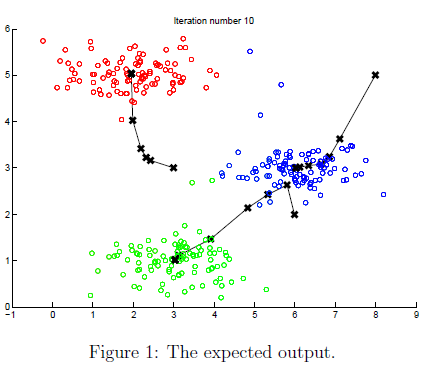

    When you run the next step, the *K*-means code will produce a visualization that steps you through the progress of the algorithm at each iteration. 

**At the command line**, **press enter multiple times to see how each step of the *****K*****-means algorithm changes the centroids and cluster assignments.** 

At the end, your figure should look as the one displayed in Figure 1.

% Load an example dataset
load('ex7data2.mat');
% Settings for running K-Means
max_iters = 10;

For consistency, here we set centroids to specific values but in practice you want to generate them automatically, such as by setting them to be random examples (as can be seen in `kMeansInitCentroids`).

initial_centroids = [3 3; 6 2; 8 5];

% Run K-Means algorithm. The 'true' at the end tells our function to plot the progress of K-Means
figure('visible','on'); hold on; 
plotProgresskMeans(X, initial_centroids, initial_centroids, idx, K, 1); 
xlabel('Press ENTER in command window to advance','FontWeight','bold','FontSize',14)
[~, ~] = runkMeans(X, initial_centroids, max_iters, true);
set(gcf,'visible','off'); hold off;

### 1.3 Random initialization

The initial assignments of centroids for the example dataset were designed so that you will see the same figure as in Figure 1. In practice, a good strategy for initializing the centroids is to select random examples from the training set. In this part of the exercise, you should complete the function `kMeansInitCentroids.m` with the following code:

The code above first randomly permutes the indices of the examples (using randperm). Then, it selects the first $K$ examples based on the random permutation of the indices. This allows the examples to be selected at random without the risk of selecting the same example twice.

*You do not need to make any submissions for this part of the exercise.*

### 1.4 Image compression with *K*-means

In this exercise, you will apply *K*-means to image compression. In a straightforward 24-bit color representation of an image, each pixel is represented as three 8-bit unsigned integers (ranging from 0 to 255) that specify the red, green and blue intensity values. This encoding is often refered to as the RGB encoding. Our image contains thousands of colors, and in this part of the exercise, you will reduce the number of colors to 16 colors. By making this reduction, it is possible to represent (compress) the photo in an efficient way. Specifically, you only need to store the RGB values of the 16 selected colors, and for each pixel in the image you now need to only store the index of the color at that location (where only 4 bits are necessary to represent 16 possibilities). 

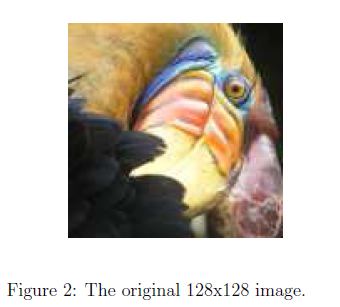

    In this exercise, you will use the *K*-means algorithm to select the 16 colors that will be used to represent the compressed image. Concretely, you will treat every pixel in the original image as a data example and use the *K*-means algorithm to find the 16 colors that best group (cluster) the pixels in the 3-dimensional RGB space. Once you have computed the cluster centroids on the image, you will then use the 16 colors to replace the pixels in the original image.

**The provided photo used in this exercise belongs to Frank Wouters and is used with his permission.*

#### 1.4.1 *K*-means on pixels

In MATLAB, images can be read in as follows:

This creates a three-dimensional matrix `A` whose first two indices identify a pixel position and whose last index represents red, green, or blue. For example, `A(50,33,3)` gives the blue intensity of the pixel at row 50 and column 33. The code below first loads the image, and then reshapes it to create an m by 3 matrix of pixel colors (where $m = 16384 = 128\times128$), and calls your *K*-means function on it.

%  Load an image of a bird
A = double(imread('bird_small.png'));
A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);

Reshape the image into an Nx3 matrix where N = number of pixels. Each row will contain the Red, Green and Blue pixel values. This gives us our dataset matrix X that we will use K-Means on.

X = reshape(A, img_size(1) * img_size(2), 3);

Run your K-Means algorithm on this data. You should try different values of K and max_iters here:

K = 16;
max_iters = 10;

When using K-Means, it is important the initialize the centroids randomly. You should complete the code in `kMeansInitCentroids.m` before proceeding

initial_centroids = kMeansInitCentroids(X, K);
% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

    After finding the top $K = 16$ colors to represent the image, you can now assign each pixel position to its closest centroid using the `findClosestCentroids` function. This allows you to represent the original image using the centroid assignments of each pixel. Notice that you have signicantly reduced the number of bits that are required to describe the image. The original image required 24 bits for each one of the $128\times128$ pixel locations, resulting in total size of $128\times128\times24 = 393,216$ bits. 

    The new representation requires some overhead storage in form of a dictionary of 16 colors, each of which require 24 bits, but the image itself then only requires 4 bits per pixel location. The final number of bits used is therefore $16\times24 + 128\times128\times4 = 65,920$ bits, which corresponds to compressing the original image by about a factor of 6. 

% Find closest cluster members
idx = findClosestCentroids(X, centroids);

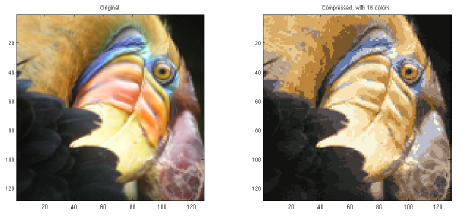

    Finally, you can view the effects of the compression by reconstructing the image based only on the centroid assignments. Specically, you can replace each pixel location with the mean of the centroid assigned to it. Figure 3 shows the reconstruction we obtained. Even though the resulting image retains most of the characteristics of the original, we also see some compression artifacts.

Essentially, now we have represented the image `X` as in terms of the indices in `idx`. We can now recover the image from the indices (`idx`) by mapping each pixel (specified by it's index in `idx`) to the centroid value.

X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square

*You do not need to make any submissions for this part of the exercise.*

### 1.5 Optional (ungraded) exercise: Use your own image

In this exercise, modify the code we have supplied to run on one of your own images. Note that if your image is very large, then *K*-means can take a long time to run. Therefore, we recommend that you resize your images to managable sizes before running the code. You can also try to vary `K` to see the effects on the compression.

## 2. Principal Component Analysis

In this exercise, you will use principal component analysis (PCA) to perform dimensionalty reduction. You will first experiment with an example 2D dataset to get intuition on how PCA works, and then use it on a bigger dataset of 5000 face image dataset. The code provided, will help you step through the first half of the exercise.

### 2.1 Example dataset

To help you understand how PCA works, you will first start with a 2D dataset which has one direction of large variation and one of smaller variation. The code below will plot the training data (Figure 4). 

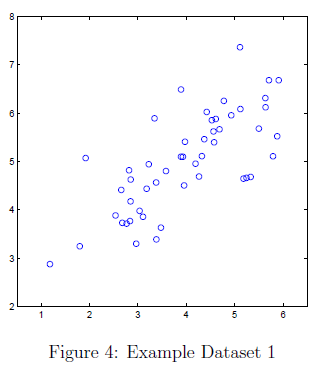

In this part of the exercise, you will visualize what happens when you use PCA to reduce the data from 2D to 1D. In practice, you might want to reduce data from 256 to 50 dimensions, say; but using lower dimensional data in this example allows us to visualize the algorithms better.

% Initialization
clear;
% The following command loads the dataset. You should now have the variable X in your environment
load ('ex7data1.mat');

% Visualize the example dataset
figure;
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;

### 2.2 Implementing PCA

In this part of the exercise, you will implement PCA. PCA consists of two computational steps: First, you compute the covariance matrix of the data. Then, you use MATLAB's `svd` function to compute the eigenvectors $U_1, U_2,\ldots,U_n$. These will correspond to the principal components of variation in the data. Before using PCA, it is important to first normalize the data by subtracting the mean value of each feature from the dataset, and scaling each dimension so that they are in the same range. In the code below, this normalization has been performed for you using the `featureNormalize` function.

    After normalizing the data, you can run PCA to compute the principal components. You task is to complete the code in `pca.m` to compute the principal components of the dataset. First, you should compute the covariance matrix of the data, which is given by:


$$\Sigma =\frac{1}{m}X^T X$$


where $X$ is the data matrix with examples in rows, and $m$ is the number of examples. Note that $\Sigma$ is a $n \times n$ matrix and not the summation operator.

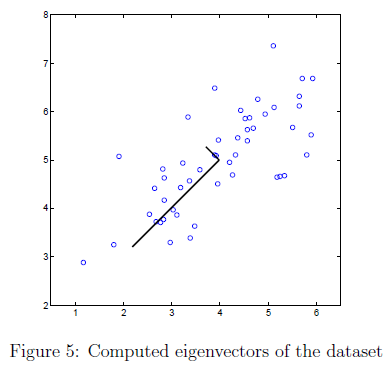

After computing the covariance matrix, you can run SVD on it to compute the principal components. In MATLAB, you can run SVD with the following command: 

where `U` will contain the principal components and `S` will contain a diagonal matrix. Once you have completed `pca.m`, the code below will run PCA on the example dataset and plot the corresponding principal components found (Figure 5). The script will also output the top principal component (eigenvector) found, and you should expect to see an output of about `[-0.707 -0.707]`. (It is possible that MATLAB may instead output the negative of this, since $U_1$ and $-U_1$ are equally valid choices for the first principal component.)

% Before running PCA, it is important to first normalize X
[X_norm, mu, ~] = featureNormalize(X);

% Run PCA
[U, S] = pca(X_norm);

% Draw the eigenvectors centered at mean of data. These lines show the directions of maximum variations in the dataset.
hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;

fprintf('Top eigenvector U(:,1) = %f %f \n', U(1,1), U(2,1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Dimensionality reduction with PCA

After computing the principal components, you can use them to reduce the feature dimension of your dataset by projecting each example onto a lower dimensional space, $x^{(i)}\rightarrow z^{(i)}$ (e.g., projecting the data from 2D to 1D). In this part of the exercise, you will use the eigenvectors returned by PCA and project the example dataset into a 1-dimensional space.

    In practice, if you were using a learning algorithm such as linear regression or perhaps neural networks, you could now use the projected data instead of the original data. By using the projected data, you can train your model faster as there are less dimensions in the input.

#### 2.3.1 Projecting the data onto the principal components

You should now complete the code in `projectData.m`. Specically, you are given a dataset `X`, the principal components `U`, and the desired number of dimensions to reduce to `K`. You should project each example in `X` onto the top `K` components in `U`. Note that the top `K` components in `U` are given by the first `K` columns of `U`, that is `U_reduce = U(:, 1:K)`.

Once you have completed the code in` projectData.m`, run the code below to project the first example onto the first dimension and you should see a value of about `1.481` (or possibly `-1.481`, if you got $-U_1$ instead of $U_1$).

% Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.2 Reconstructing an approximation of the data

After projecting the data onto the lower dimensional space, you can approximately recover the data by projecting them back onto the original high dimensional space. Your task is to complete `recoverData.m` to project each example in `Z` back onto the original space and return the recovered approximation in `X_rec`. Once you have completed the code in `recoverData.m`, the code below will recover an approximation of the first example and you should see a value of about `[-1.047 -1.047]`.

X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.3 Visualizing the projections

After completing both `projectData` and `recoverData`, the code in this section will perform both the projection and approximate reconstruction to show how the projection affects the data. In Figure 6, the original data points are indicated with the blue circles, while the projected data points are indicated with the red circles. The projection effectively only retains the information in the direction given by $U_1$.

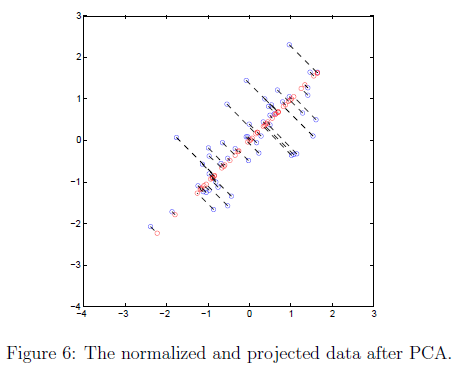

%  Plot the normalized dataset (returned from pca)
plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square
%  Draw lines connecting the projected points to the original points
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

### 2.4 Face image dataset

In this part of the exercise, you will run PCA on face images to see how it can be used in practice for dimension reduction. The dataset `ex7faces.mat` contains a dataset* `X` of face images, each $32 \times 32$ in grayscale. 

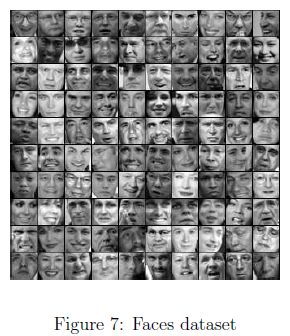

Each row of `X` corresponds to one face image (a row vector of length 1024). The code in this section will load and visualize the first 100 of these face images (Figure 7).

%  Load Face dataset
load ('ex7faces.mat')
%  Display the first 100 faces in the dataset
displayData(X(1:100, :));

**This dataset was based on a cropped version of the*[ *labeled faces in the wild dataset*](http://vis-www.cs.umass.edu/lfw/)*.*

#### 2.4.1 PCA on faces

To run PCA on the face dataset, we first normalize the dataset by subtracting the mean of each feature from the data matrix `X`. The code below will do this for you and then run your PCA code. After running PCA, you will obtain the principal components of the dataset. Notice that each principal component in `U` (each row) is a vector of length $n$ (where for the face dataset, $n = 1024$). It turns out that we can visualize these principal components by reshaping each of them into a $32 \times 32$ matrix that corresponds to the pixels in the original dataset. 

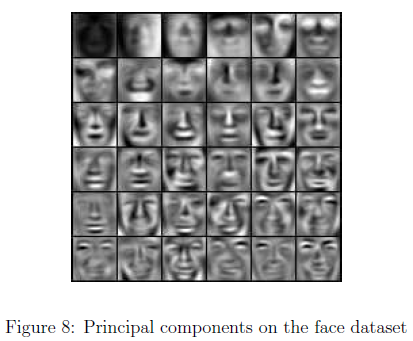

The code below displays the first 36 principal components that describe the largest variations (Figure 8).  If you want, you can also change the code to display more principal components to see how they capture more and more details. Before running PCA, it is important to first normalize `X` by subtracting the mean value from each feature.

[X_norm, ~, ~] = featureNormalize(X);

% Run PCA
[U, ~] = pca(X_norm);

% Visualize the top 36 eigenvectors found
displayData(U(:, 1:36)');

The code below will project the face dataset onto only the first 100 principal components. Concretely, each face image is now described by a vector $z^{(i)}\in\mathbb{R}^{100}$. 

K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: %d x %d', size(Z));

To understand what is lost in the dimension reduction, you can recover the data using only the projected dataset. In the code below, an approximate recovery of the data is performed and the original and projected face images are displayed side by side (Figure 9). 

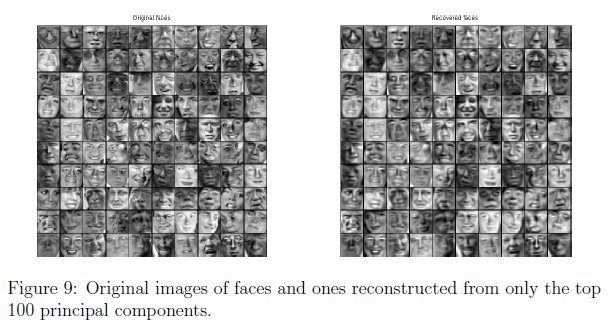

From the reconstruction, you can observe that the general structure and appearance of the face are kept while the fine details are lost. This is a remarkable reduction (more than $10\times$) in the dataset size that can help speed up your learning algorithm signicantly. For example, if you were training a neural network to perform person recognition (gven a face image, predict the identitfy of the person), you can use the dimension reduced input of only a 100 dimensions instead of the original pixels.

X_rec  = recoverData(Z, U, K);

% Display normalized data
subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

% Display reconstructed data from only k eigenfaces
subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

### 2.5 Optional (ungraded) exercise: PCA for visualization

In the earlier *K*-means image compression exercise, you used the *K*-means algorithm in the 3-dimensional RGB space. In this section, we have provided code to visualize the final pixel assignments in this 3D space using the `scatter3` function. Each data point is colored according to the cluster it has been assigned to. You can select the rotate icon and then drag your mouse on the figure to rotate and inspect this data in 3 dimensions.

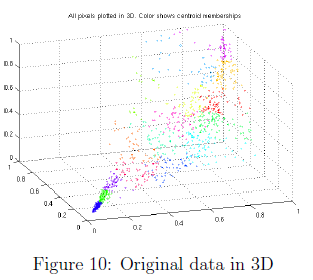

clear;
% Re-load the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));
A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');

    It turns out that visualizing datasets in 3 dimensions or greater can be cumbersome. Therefore, it is often desirable to only display the data in 2D even at the cost of losing some information. In practice, PCA is often used to reduce the dimensionality of data for visualization purposes. In the code below, the script will apply your implementation of PCA to the 3-dimensional data to reduce it to 2 dimensions and visualize the result in a 2D scatter plot. The PCA projection can be thought of as a rotation that selects the view that maximizes the spread of the data, which often corresponds to the 'best' view.

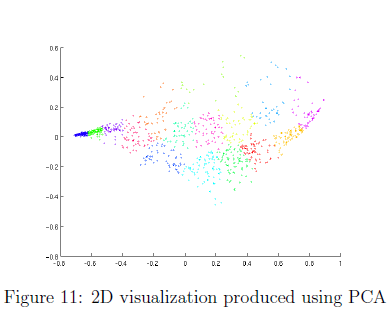

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored. 

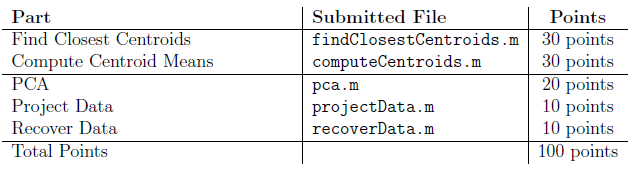

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.